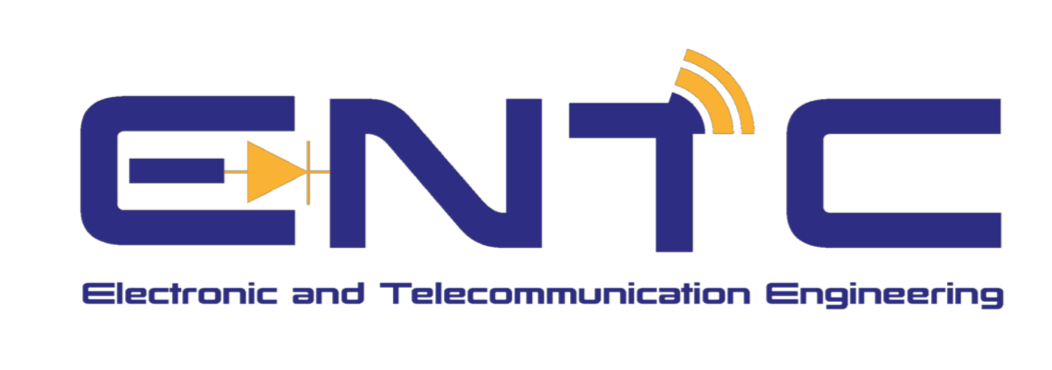

# EN 2040

# Random Signal and Processes

### Simulation Assignment

`A.G.N.Udara 190636M`

## The document is created using MATLAB R2020a Live Editor.


$$Question \;1$$


`Given that the probability of the genarated bit being either 1 or 0 is equal, we can use `$randi$ function. 

binary_seq=randi([0,1],1,1000);

`Now to create the square pulses according to the binary sequence we generated,`

A=1;
S_seq=[];
for k1 = 1:length(binary_seq)
    if binary_seq(1,k1) == 0
        S_seq(k1)=-A;
    else
        S_seq(k1)=A;
    end
end


$$Question\;
2$$


`To generate the Additive White Gaussian Noise(AWGN), we will generate a normally distributed value set using `$randn$` function.`

`After that we can convert it to any gaussian model we like with,`

#### 
$$z= \frac{x-\mu }{\sigma}$$


normal_seq=randn(1,1000);

`now with `$\mu = 0$` and `$\sigma^2$`=1, generate our AWGN,`

agwn_1=1*normal_seq + 0;


$$Question\;3$$


`First we will plot the `$R$ `with the AWGN with variance 1,`

`Here `

#### 
$$R=S+N$$


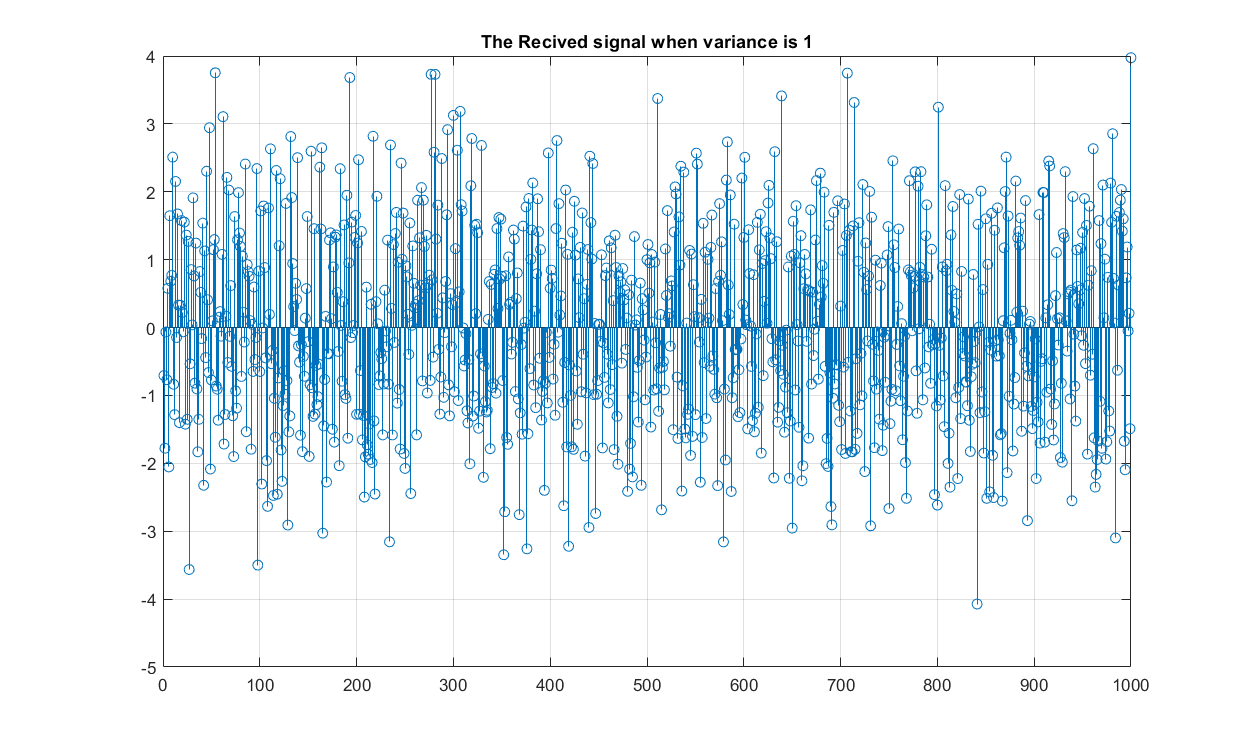

R_seq1=S_seq+agwn_1;
figure('Renderer','painters','Position',[10 10 1000 600]);
stem(R_seq1)

xlim('auto')
ylim('auto')
title('The Recived signal when variance is 1')
grid on

`This is not clear, so we will take a portion for the plotting`

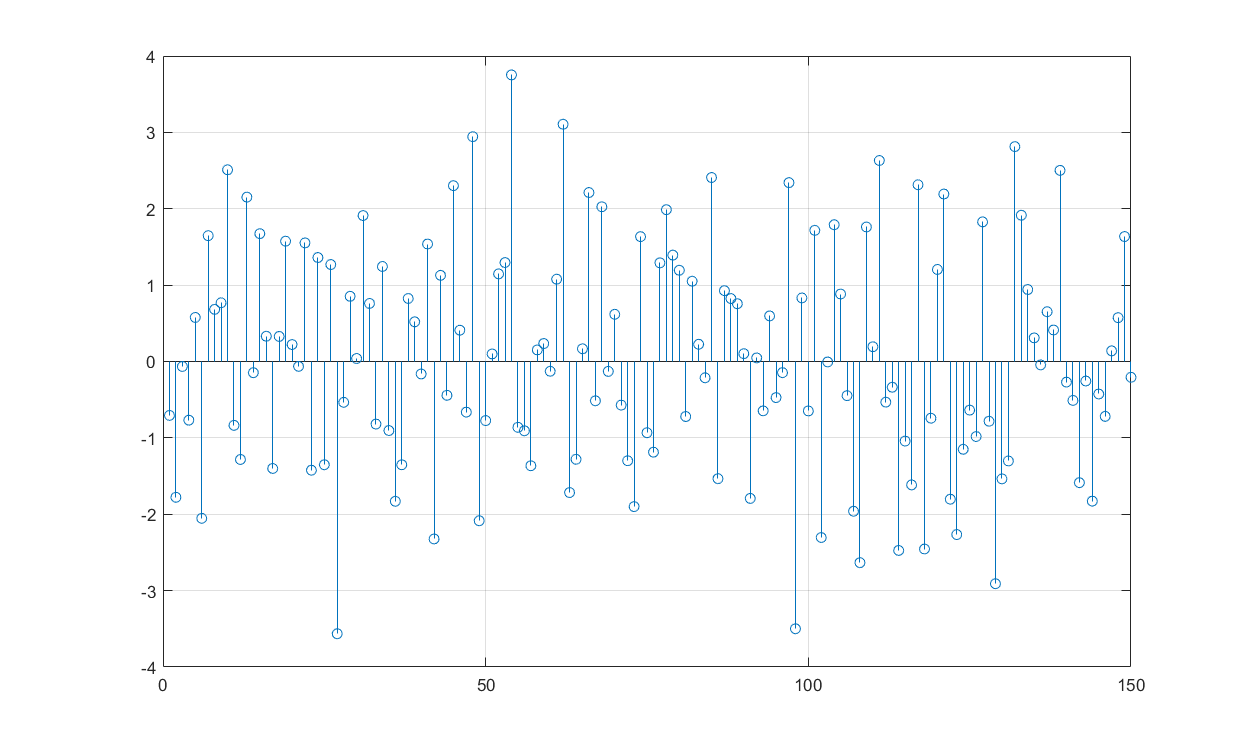

idx=1:150;

figure('Renderer','painters','Position',[10 10 1000 600]);
stem(R_seq1(idx))

grid on

`Now we will plot multiple scenarios by changing variance `$\sigma^2$

`for` $\sigma^2$=`{1,2,3,4,5}`  `we will check for the same noise,`

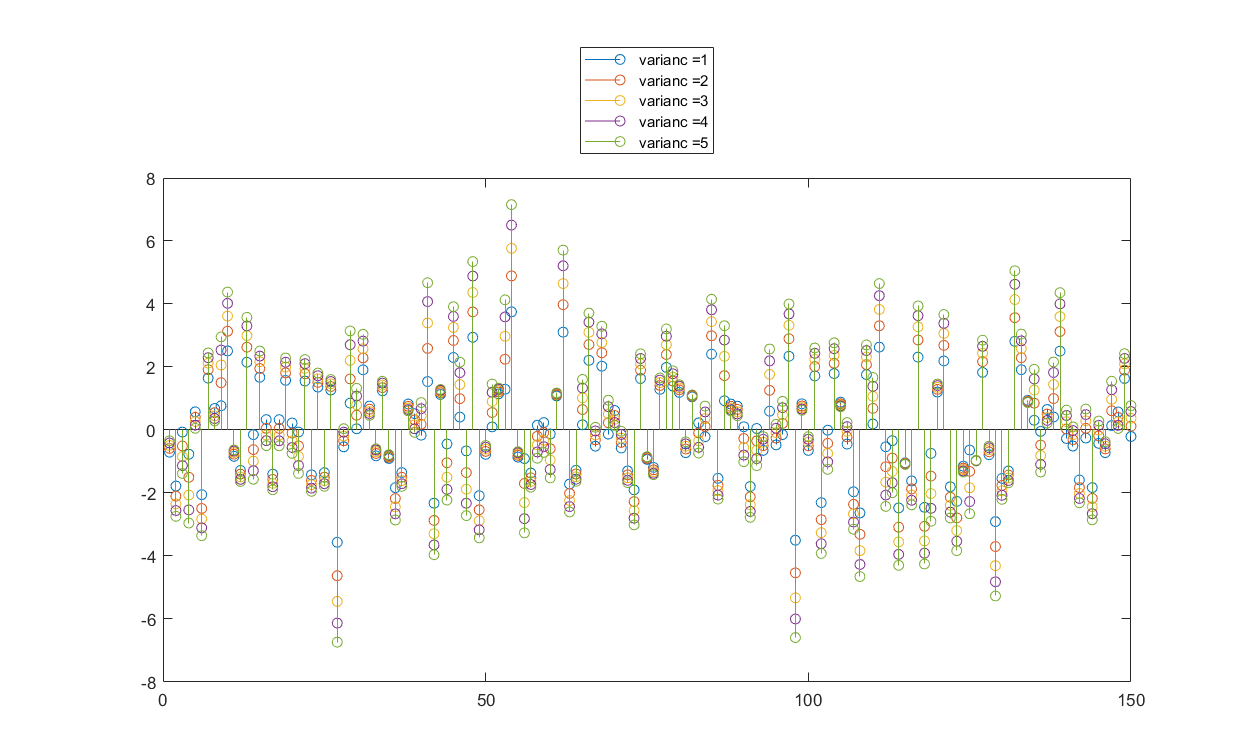

agwn_2=sqrt(2)*normal_seq + 0;
agwn_3=sqrt(3)*normal_seq + 0;
agwn_4=sqrt(4)*normal_seq + 0;
agwn_5=sqrt(5)*normal_seq + 0;

R_seq2=S_seq+agwn_2;
R_seq3=S_seq+agwn_3;
R_seq4=S_seq+agwn_4;
R_seq5=S_seq+agwn_5;

figure('Renderer','painters','Position',[10 10 1000 600]);
p1=stem(R_seq1(idx));hold on;

p2=stem(R_seq2(idx));

p3=stem(R_seq3(idx));

p4=stem(R_seq4(idx));

p5=stem(R_seq5(idx));hold off;
h=[p1(),p2(),p3(),p4(),p5()];
legend(h,'varianc =1','varianc =2','varianc =3','varianc =4','varianc =5',"Location","northoutside")
xlim('auto')
ylim('auto')

`When we observe the above stem plots, we can see that when variance increase, the output is also  shifted. So, with`

`more variance, we can say that possibility of an error is also increased.`


$$Question\;4$$


`For `$\sigma^2=1$` , we will decode the R sequence as Y, with the threshold , `$\tau =0$`since the sender sequence is symmetric around 0, and get`


$$$Y\;= +A \; for \; S>0 \; or \; \; -A \; for \; S \le 0 $$$


Y_seq=[];
tao=0;
for k1 = 1:length(binary_seq)
    if R_seq1(1,k1) <= tao
        Y_seq(k1)=-A;
    else
        Y_seq(k1)=A;
    end
end

`Now we will plot both sender and receiver side by side`

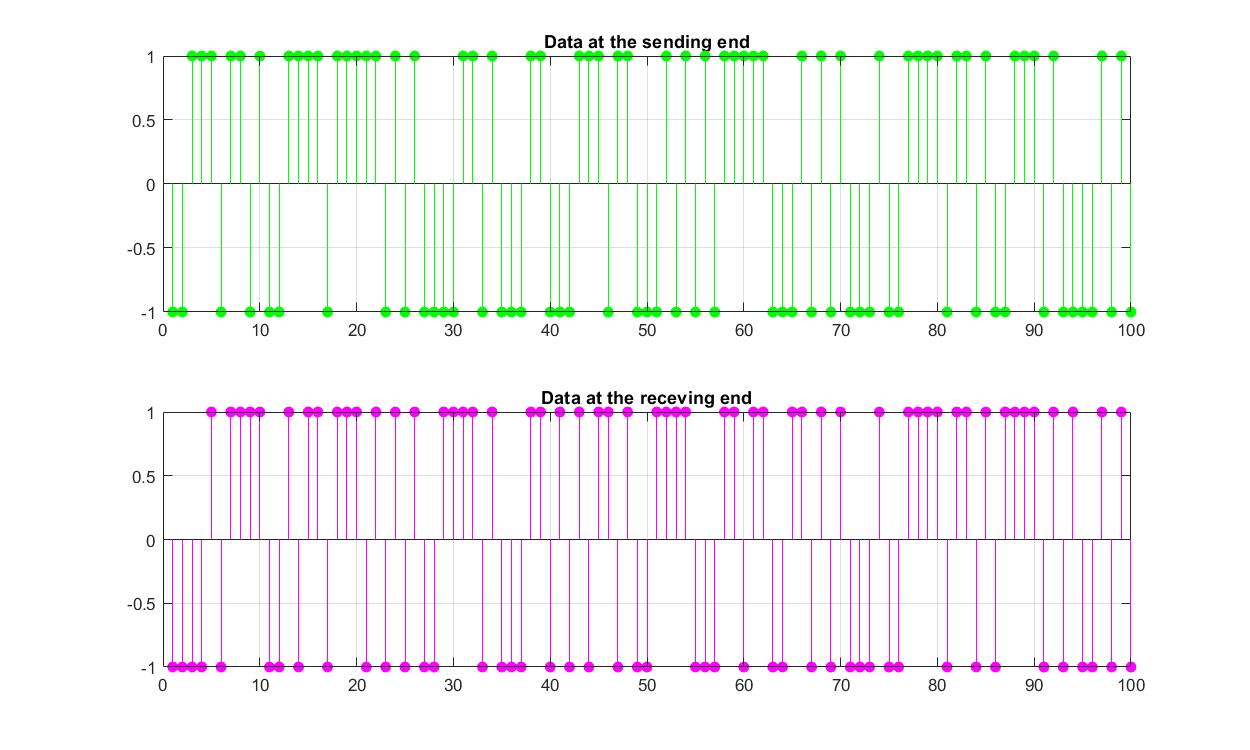

idx3=1:100;
subplot(2,1,1)
stem(S_seq(idx3),'filled','Color','g')
title('Data at the sending end')
subplot(2,1,2)
stem(Y_seq(idx3),'filled','Color','m')
title('Data at the receving end')
subplot(2,1,1)
xlim([0.0 100.0])
ylim([-1.00 1.00])
grid on
subplot(2,1,2)
xlim([0.0 100.0])
ylim([-1.00 1.00])
grid on

`Next, we will check for errors, If there are errors, we can compare those elements`

errored_seq=[];

for k1 = 1:length(Y_seq)
    if Y_seq(1,k1) == S_seq(1,k1)
        errored_seq(1,k1)=0;
        errored_seq(2,k1)=0;
    else
        errored_seq(1,k1)=S_seq(1,k1);
        errored_seq(2,k1)=Y_seq(1,k1);
    end
end

`Now we will plot and compare`

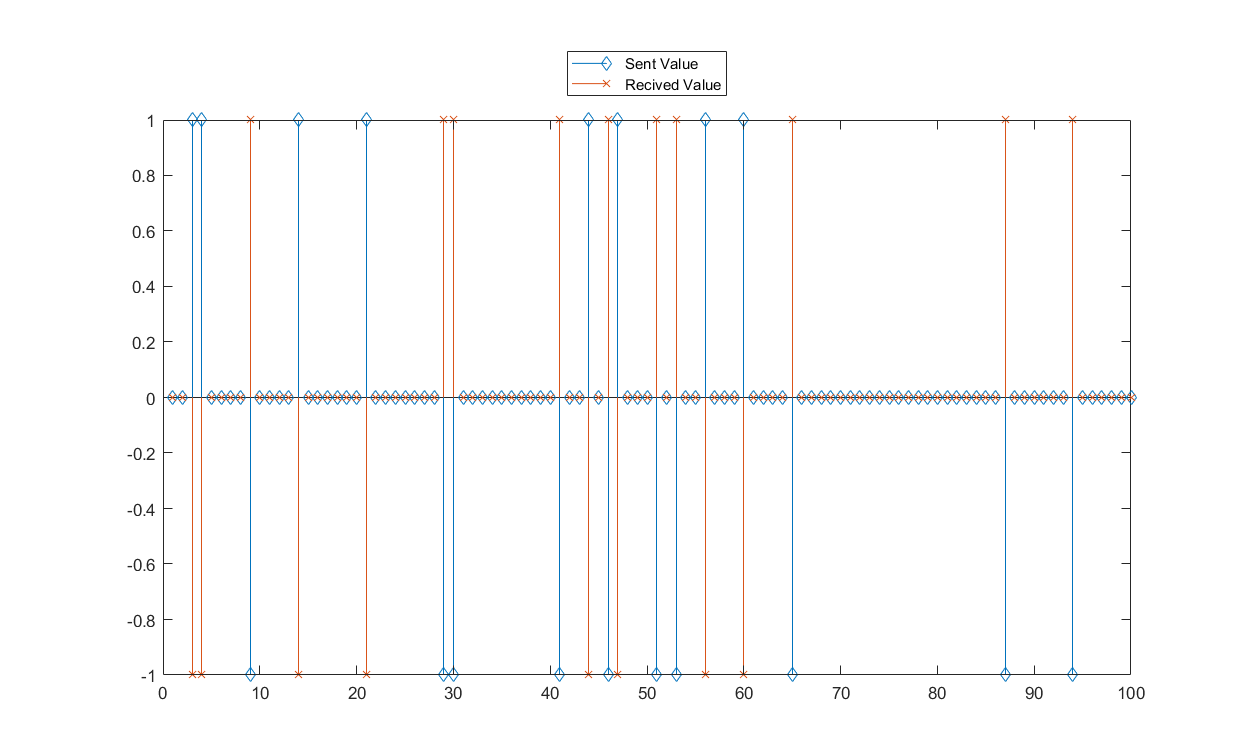

figure('Renderer','painters','Position',[10 10 1000 600]);
p6=stem(errored_seq(1,(idx3)),'Marker',"diamond");hold on;

p7=stem(errored_seq(2,(idx3)),'Marker',"x");hold off;

j=[p6(),p7()];
legend(j,'Sent Value','Recived Value','Location',"northoutside")
xlim('auto')
ylim('auto')

`We can see that there are many errors. There are single bit errors and also burst errors.`


$$Question\;5$$


`Now we have to redo the above steps for `$L=100000$,

binary_seq2=randi([0,1],1,100000);

A2=1;
S_seq2=[];
for k1 = 1:length(binary_seq2)
    if binary_seq2(1,k1) == 0
        S_seq2(k1)=-A2;
    else
        S_seq2(k1)=A2;
    end
end

normal_seq_2=randn(1,100000);
%Get the gaussian noise with varaince of 1

agwn_1_2=1*normal_seq_2 + 0;

%Recived sequance
R_seq1_2=S_seq2+agwn_1_2;

%Decode with tau=0 
Y_seq_2=[];
tao_2=0;
for k1 = 1:length(binary_seq)
    if R_seq1_2(1,k1) <= tao_2
        Y_seq_2(k1)=-A2;
    else
        Y_seq_2(k1)=A2;
    end
end



`Now we will plot histograms.`

`for 10 bins, first we will generate a histogram manually.`

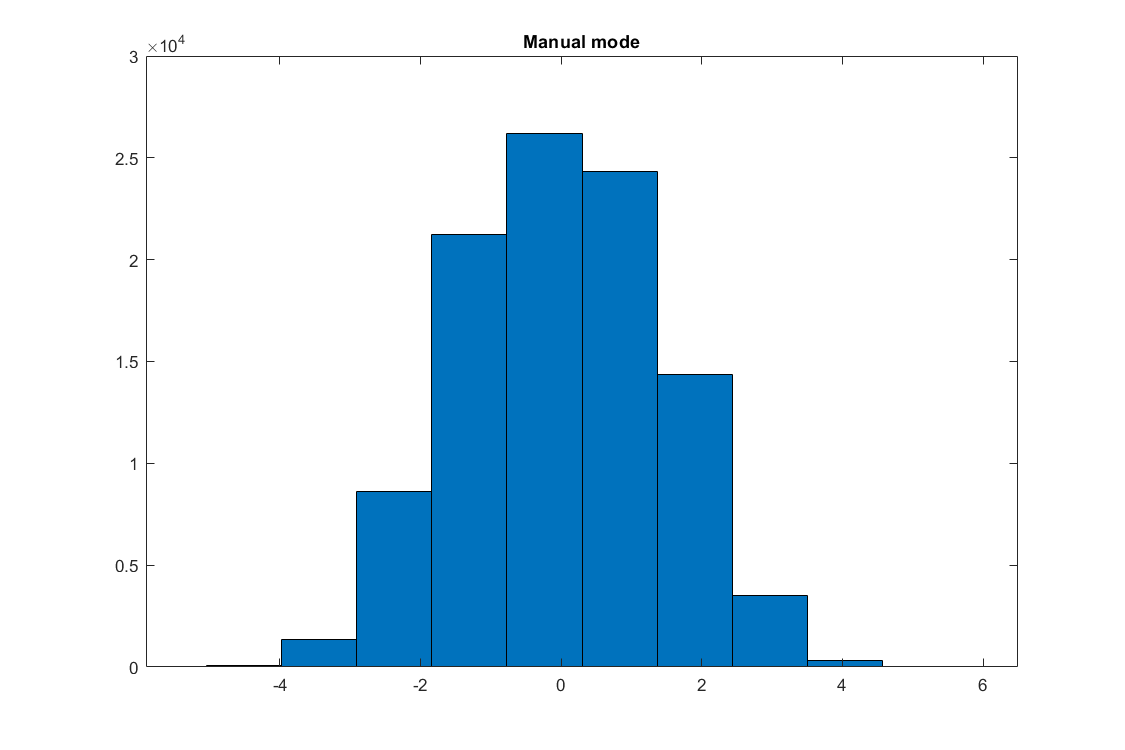

%Find the bounds of the sequance
Max_x=max(R_seq1_2);
Min_x=min(R_seq1_2);

Bins=10;

% Make partitions in the given range to get "Bins" number of bins

x_values_1=linspace(Min_x,Max_x,Bins+1);


count_10_1 =zeros(1,10);

%now count each element and get the total count 
for k1 = 1:length(R_seq1_2)
    for k2=2:length(x_values_1)  % take upper bound of each partition and compare;
        if R_seq1_2(k1)<=x_values_1(k2)
            count_10_1(1,k2-1)=count_10_1(1,k2 - 1)+1; %Increment the count by one and break
            break
        end
    end
end

%creat the mid values for the bins
x_mids_10_1= (x_values_1(1,2:11) + x_values_1(1,1:10))/2;

%plot the bar diagram with calculated data

figure('Renderer','painters','Position',[10 10 900 600]);

bar(x_mids_10_1,count_10_1,1);
title('Manual mode'); %Now using built in function hist()

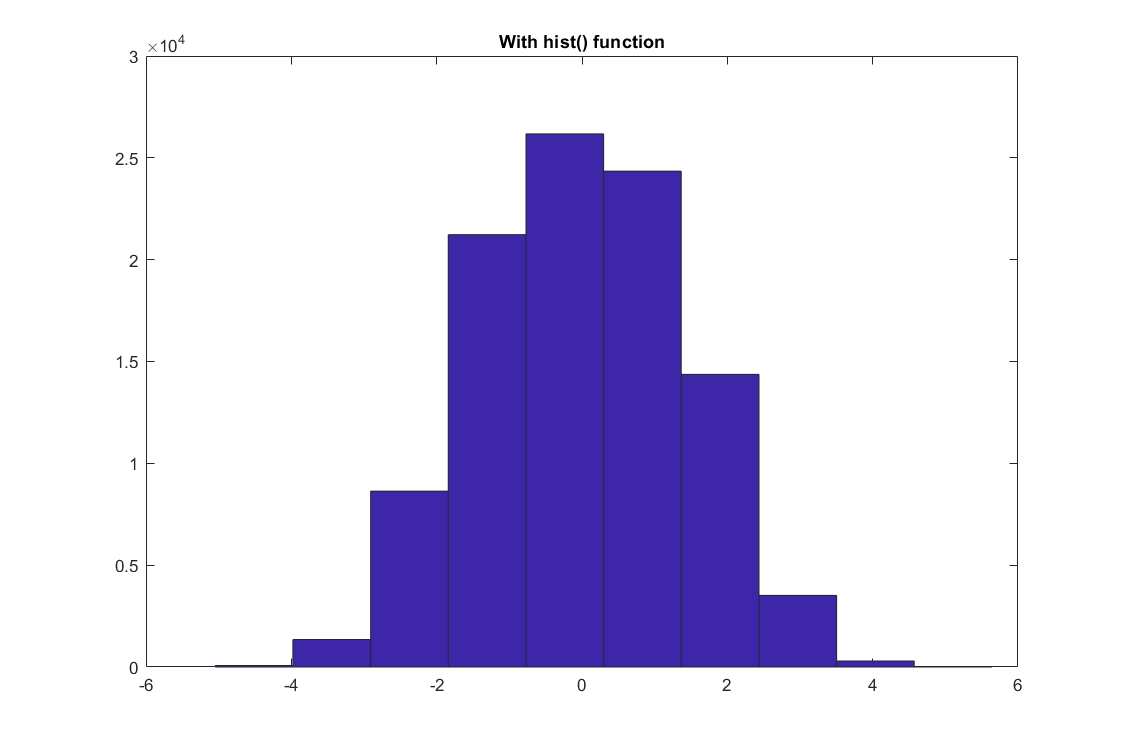


figure('Renderer','painters','Position',[10 10 900 600]);
hist(R_seq1_2,Bins);
title('With hist() function')

`They seem identical. But the edges are not smooth. Since we must limit the X axis values, this is not suitable.`


$$Part \; a$$


`Now we will check for different number of bits bins,`

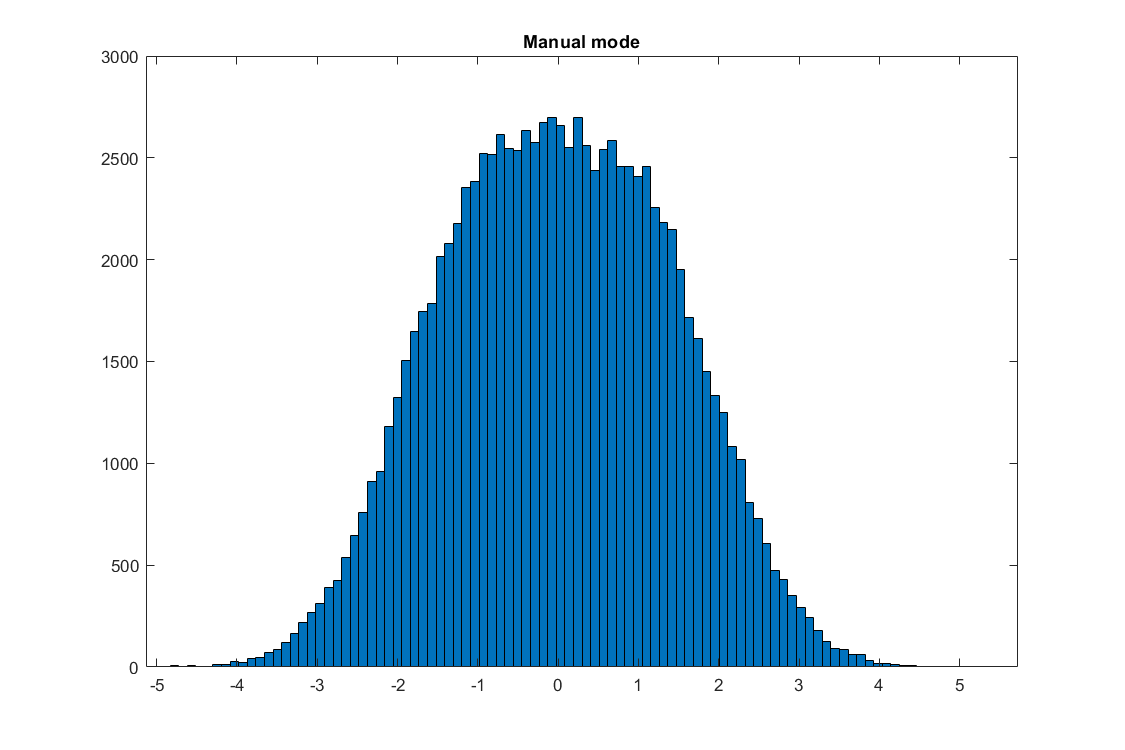

new_bin=100;
Max_x=max(R_seq1_2);
Min_x=min(R_seq1_2);


% Make partitions in the given range to get "Bins" number of bins

x_values_2=linspace(Min_x,Max_x,new_bin+1);


count_2 =zeros(1,new_bin);

%now count each element and get the total count
for k1 = 1:length(R_seq1_2)
    for k2=2:length(x_values_2)  % take upper bound of each partition and compare;
        if R_seq1_2(k1)<=x_values_2(k2)
            count_2(1,k2-1)=count_2(1,k2 - 1)+1; %Increment the count by one and break
            break
        end
    end
end

%creat the mid values for the bins
x_mids_2= (x_values_2(1,2:new_bin+1) + x_values_2(1,1:new_bin))/2;

%plot the bar diagram with calculated data

figure('Renderer','painters','Position',[10 10 900 600]);

bar(x_mids_2,count_2,1);
title('Manual mode'); %Now using built in function hist()

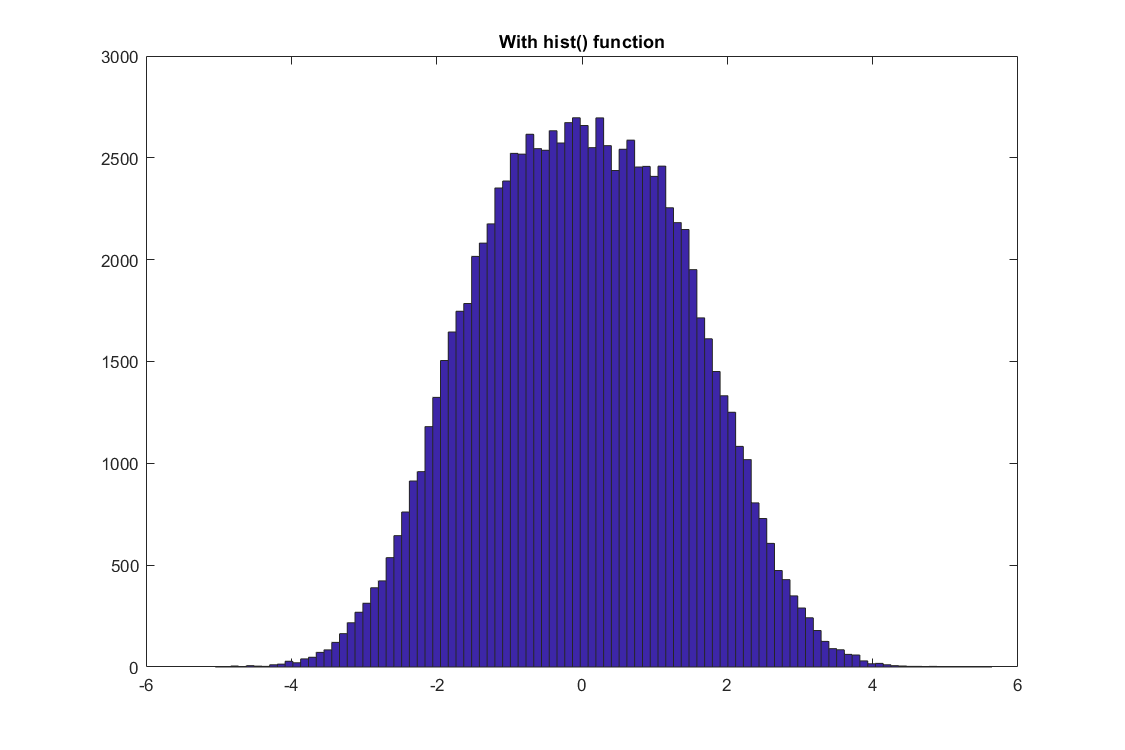


figure('Renderer','painters','Position',[10 10 900 600]);
hist(R_seq1_2,new_bin);
title('With hist() function')

`When we increased number of bins, both plots keep their similarity. But with high count of bins, we get more smooth`

`data.`

`So, using 100 bins is acceptable. Since we limit number of values in X axis, considering large number of bins will`

`increase` `the accuracy too.`


$$Part \; b$$


`Now to get conditional probabilities, we will simply check what will happen when the input is +A and when -A separately.`

`We will Use the same bin numbers as above. (Since higher number of mid values give, smoother pdf)`

`The logic behind will be,`

`when the input is equal to ± A, what we will receive at receive at the receiving end and use a normalized histogram`

`to show probabilities of`

`each receiving end values.`

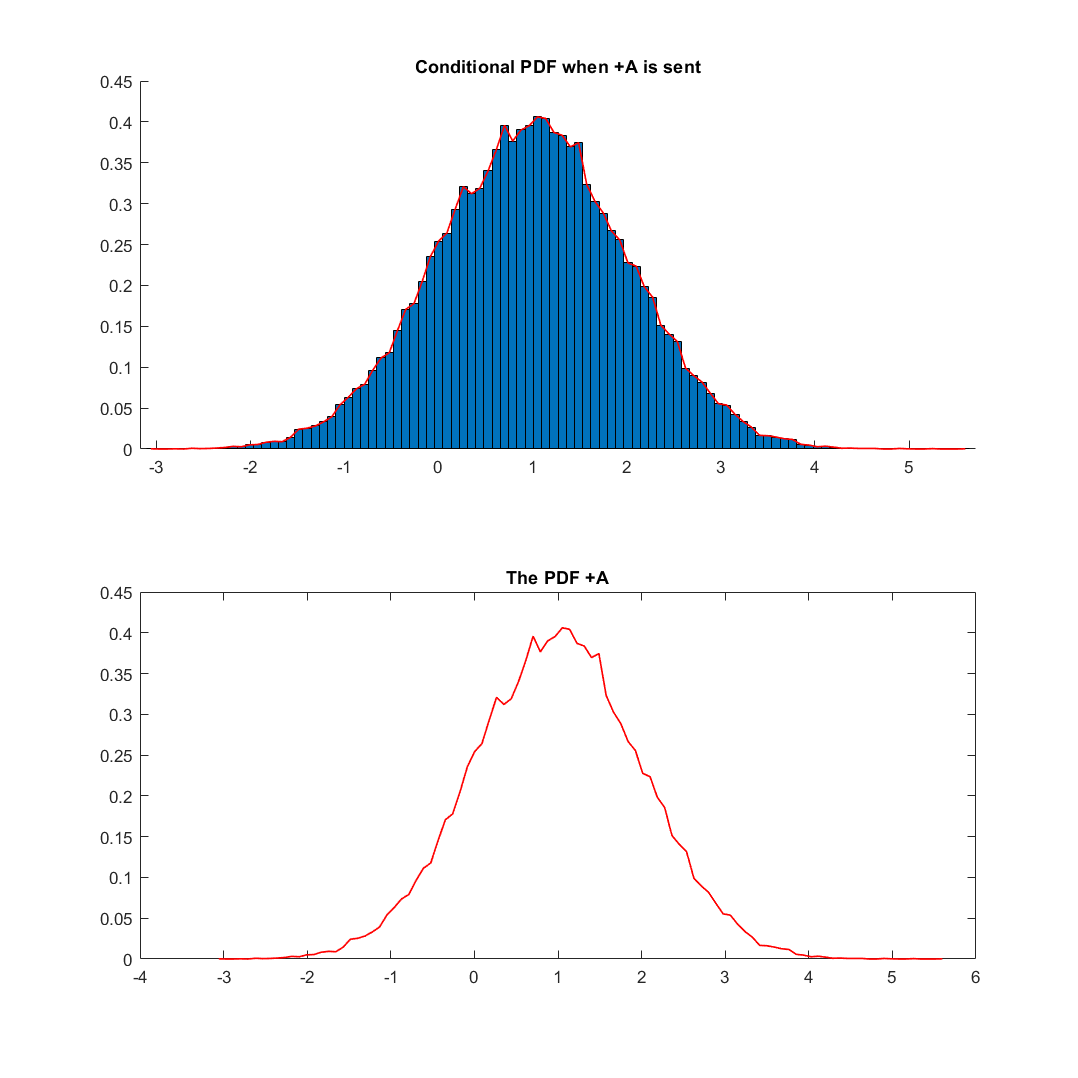

recived_end_Positive_1=[];
recived_end_Negative_1=[];
%since we need to compare A values,
A3=1;
for k1=1:length(S_seq2)
    if S_seq2(k1)==A3 % If the send value is +A
        recived_end_Positive_1(end+1)=R_seq1_2(k1);
    else %If the sent value is -A,
        recived_end_Negative_1(end+1)=R_seq1_2(k1); %When S=-A R(p) should be added to Rn
    end
end
 

% now we will plot the histograms   
  
Max_Positve_1=max(recived_end_Positive_1);
Min_Positive_1=min(recived_end_Positive_1);


% Make partitions in the given range to get "Bins" number of bins

x_values_3_positive_1=linspace(Min_Positive_1,Max_Positve_1,new_bin+1);


count_3_positive_1 =zeros(1,new_bin);

%now count each element and get the total count
for k1 = 1:length(recived_end_Positive_1)
    for k2=2:length(x_values_3_positive_1)  % take upper bound of each partition and compare;
        if recived_end_Positive_1(k1)<=x_values_3_positive_1(k2)
            count_3_positive_1(1,k2-1)=count_3_positive_1(1,k2 - 1)+1; %Increment the count by one and break
            break
        end
    end
end

%create the mid values for the bins
x_mids_3_Positive_1= (x_values_3_positive_1(1,2:new_bin+1) + x_values_3_positive_1(1,1:new_bin))/2;

%normalize the pdf
width_postive_1=(abs(Min_Positive_1)+abs(Max_Positve_1))/new_bin;
count_3_positive_1=count_3_positive_1/(length(recived_end_Positive_1)*width_postive_1);
%plot the bar diagram with calculated data
figure('Renderer','painters','Position',[10 10 1200 1200]);
subplot(2,1,1)
hold on
bar(x_mids_3_Positive_1,count_3_positive_1,1);
title('Conditional PDF when +A is sent'); %Now using built in function hist()
plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
hold off;
subplot(2,1,2)
plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
title("The PDF +A")

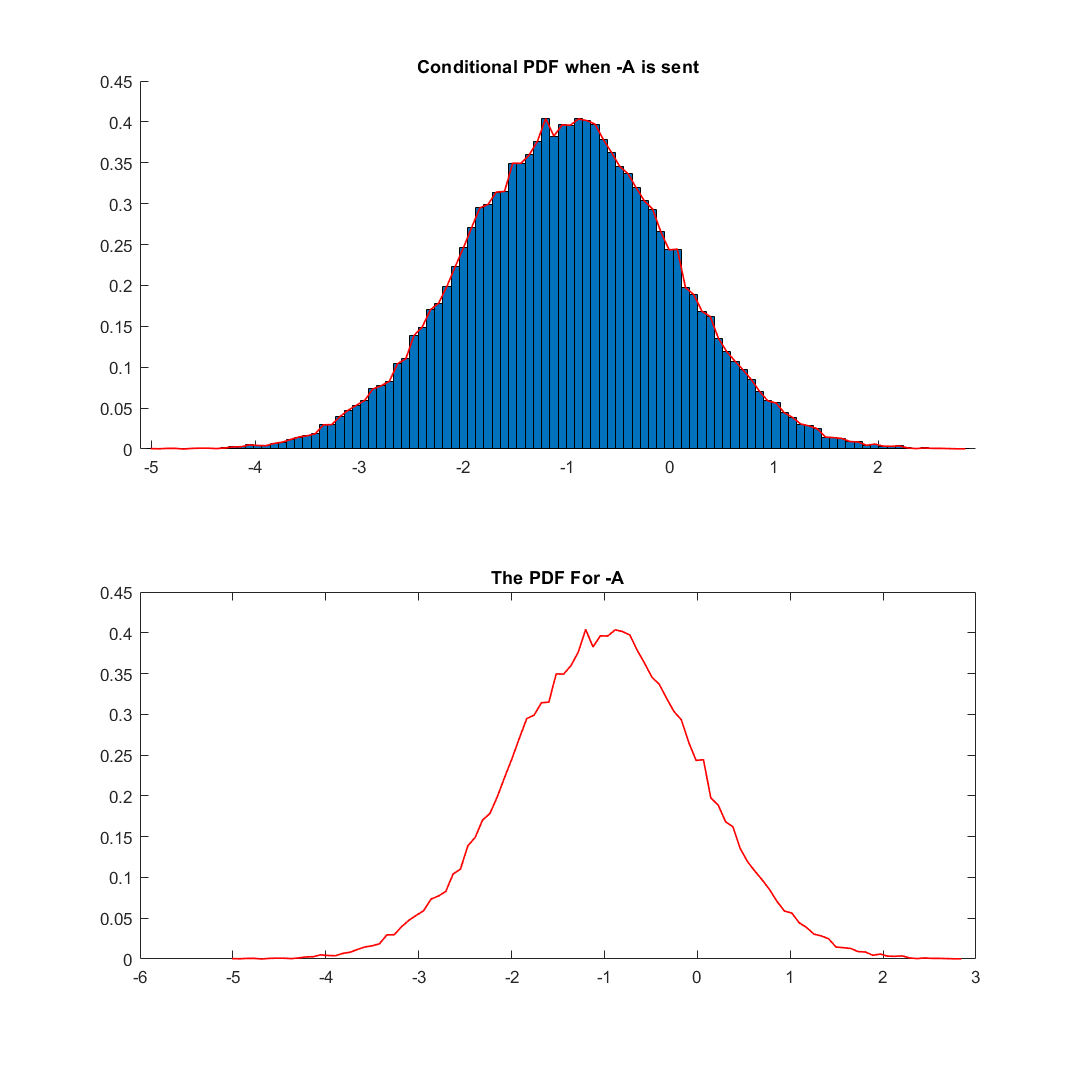

% now we will plot the histograms for -A
  
Max_Negative_1=max(recived_end_Negative_1);
Min_Negative_1=min(recived_end_Negative_1);


% Make partitions in the given range to get "Bins" number of bins

x_values_3_neagtive_1=linspace(Min_Negative_1,Max_Negative_1,new_bin+1);


count_3_negative_1 =zeros(1,new_bin);

%now count each element and get the total count
for k1 = 1:length(recived_end_Negative_1)
    for k2=2:length(x_values_3_neagtive_1)  % take upper bound of each partition and compare;
        if recived_end_Negative_1(k1)<=x_values_3_neagtive_1(k2)
            count_3_negative_1(1,k2-1)=count_3_negative_1(1,k2 - 1)+1; %Increment the count by one and break
            break
        end
    end
end

%create the mid values for the bins
x_mids_3_Negative_1= (x_values_3_neagtive_1(1,2:new_bin+1) + x_values_3_neagtive_1(1,1:new_bin))/2;

%normalize the pdf
width_postive_1=(abs(Min_Negative_1)+abs(Max_Negative_1))/new_bin;
count_3_negative_1=count_3_negative_1/(length(recived_end_Negative_1)*width_postive_1);
%plot the bar diagram with calculated data
figure('Renderer','painters','Position',[10 10 1200 1200]);
subplot(2,1,1)
hold on
bar(x_mids_3_Negative_1,count_3_negative_1,1);
title('Conditional PDF when -A is sent'); %Now using built in function hist()
plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
hold off;
subplot(2,1,2)
plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
title("The PDF For -A")

`Now let’s repeat what we did earlier with different A values, `

`For A= {1,2,3,4} we will draw PDFs``We will get data to calculate respective Expected Values from here too. (`$Part\;C$)

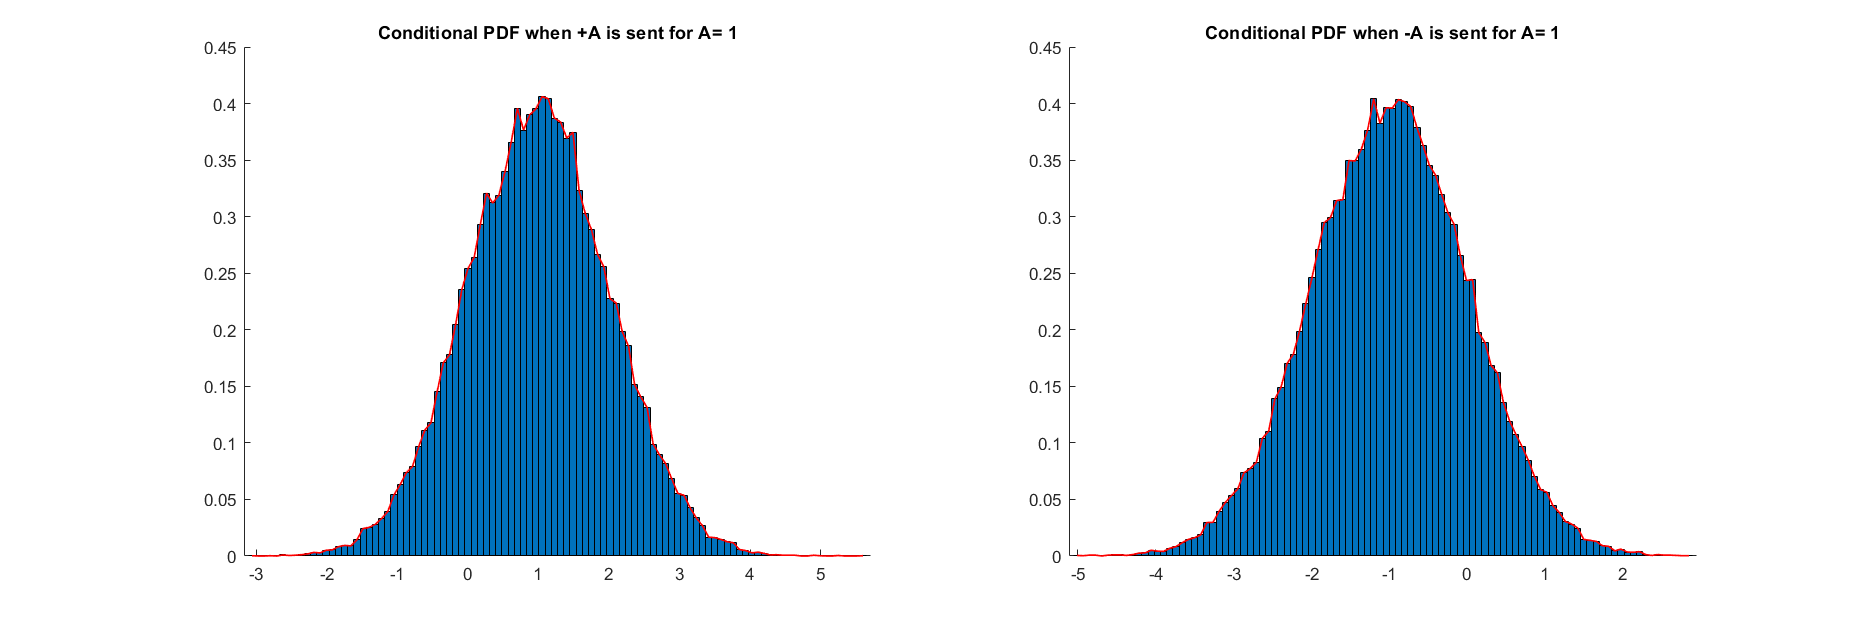

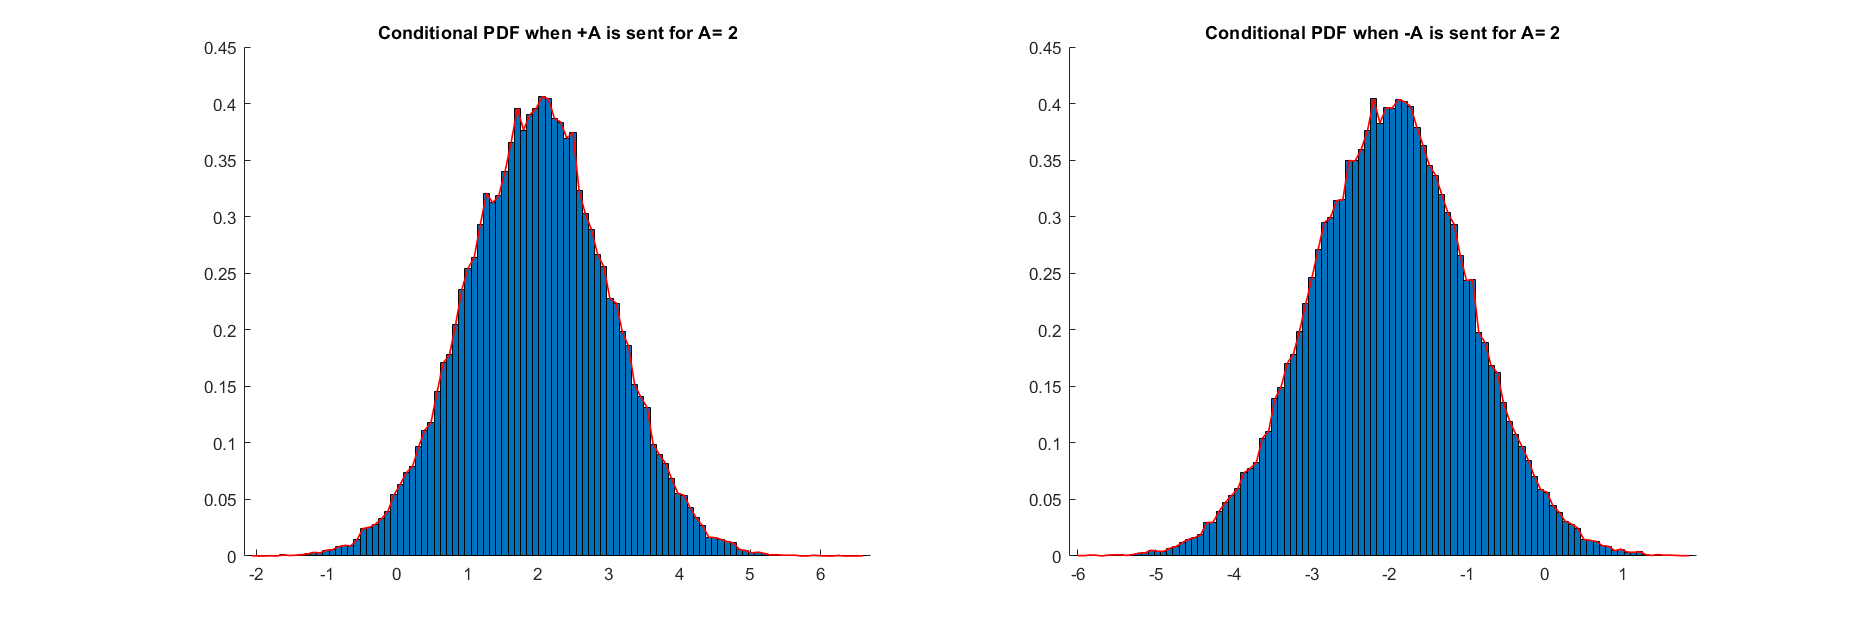

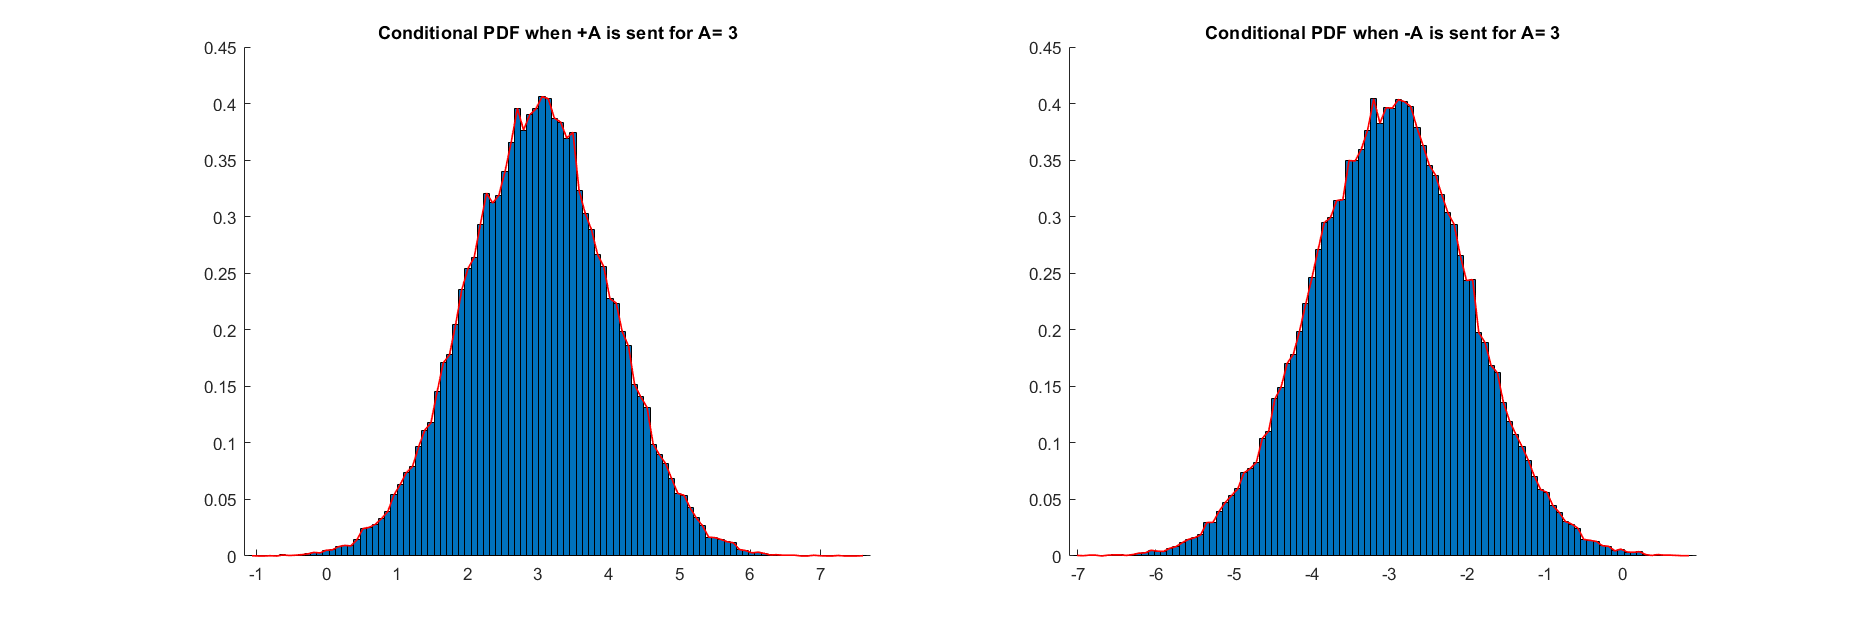

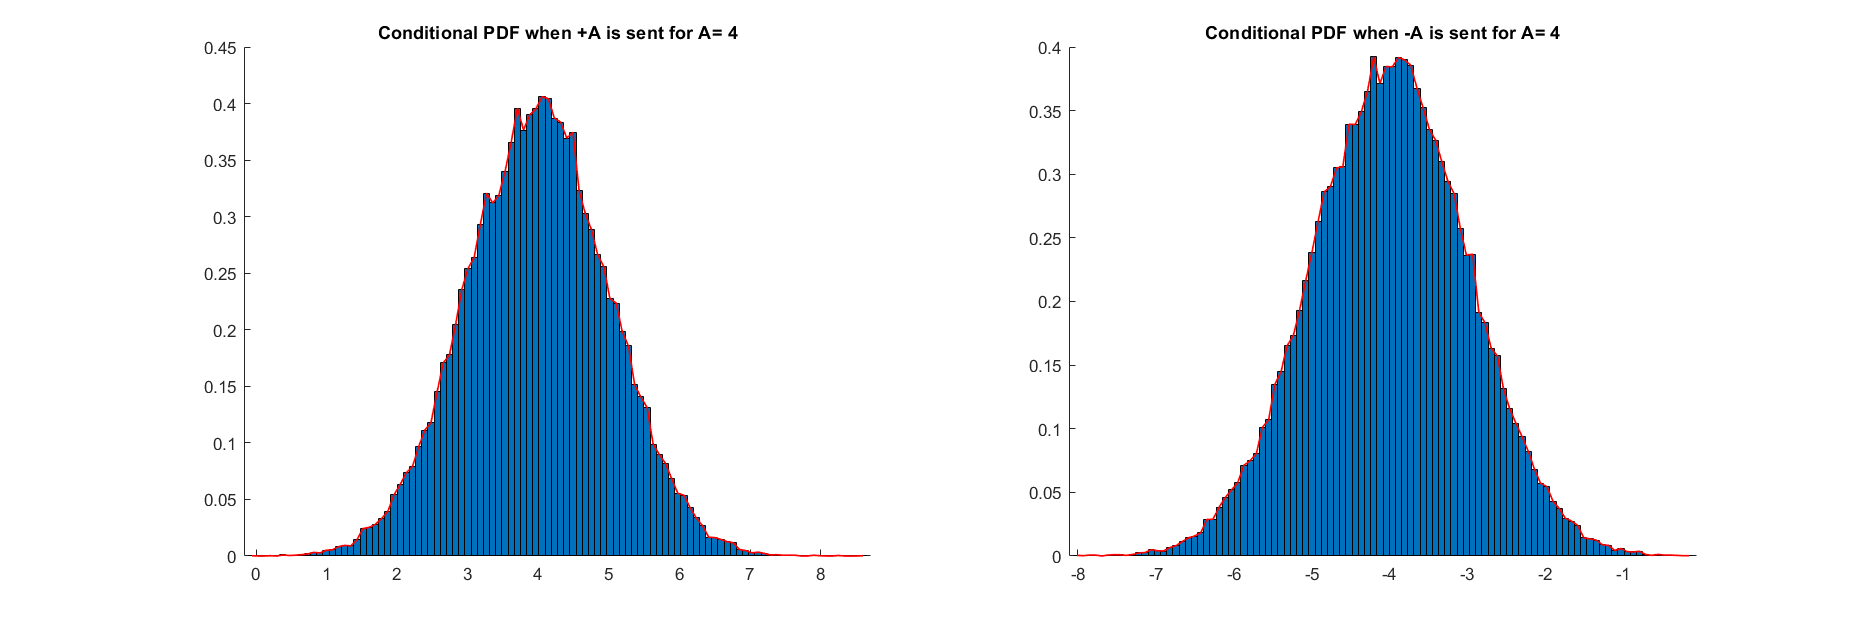

X_Values_array_positive=[];
X_Values_array_negative=[];
Y_Values_array_positive=[];
Y_Values_array_negative=[];
Rec_Values_array_total=[];
Width_values_array_negative=[];
Width_values_array_positive=[];
for AX=1:1:4
    
    
    S_seq3=[];
    for k1 = 1:length(binary_seq2)
        if binary_seq2(1,k1) == 0
            S_seq3(k1)=-AX;
        else
            S_seq3(k1)=AX;
        end
    end
    
    %Get the gaussian noise with varaince of 1
    
    agwn_1_3=1*normal_seq_2 + 0;
    
    %Recived sequance
    R_seq1_2=S_seq3+agwn_1_3;
    
    Rec_Values_array_total(end+1, :)=R_seq1_2;

    %Decode with tau=0
    Y_seq_3=[];
    tao_2=0;
    for k1 = 1:length(binary_seq)
        if R_seq1_2(1,k1) <= tao_2
            Y_seq_3(k1)=-AX;
        else
            Y_seq_3(k1)=AX;
        end
    end
    
    
    recived_end_Positive_1=[];
    recived_end_Negative_1=[];
    %since we need to compare A values,
    
    for k1=1:length(S_seq3)
        if S_seq3(k1)==AX % If the send value is +A
            recived_end_Positive_1(end+1)=R_seq1_2(k1);
        else %If the sent value is -A,
            recived_end_Negative_1(end+1)=R_seq1_2(k1); %When S=-A R(p) should be added to Rn
        end
        
    end
    
    
    % now we will plot the histograms
    
    Max_Positve_1=max(recived_end_Positive_1);
    Min_Positive_1=min(recived_end_Positive_1);
    
    
    % Make partitions in the given range to get "Bins" number of bins
    
    x_values_3_positive_1=linspace(Min_Positive_1,Max_Positve_1,new_bin+1);
    
    
    count_3_positive_1 =zeros(1,new_bin);
    
    %now count each element and get the total count
    for k1 = 1:length(recived_end_Positive_1)
        for k2=2:length(x_values_3_positive_1)  % take upper bound of each partition and compare;
            if recived_end_Positive_1(k1)<=x_values_3_positive_1(k2)
                count_3_positive_1(1,k2-1)=count_3_positive_1(1,k2 - 1)+1; %Increment the count by one and break
                break
            end
        end
    end
    
    %create the mid values for the bins
    x_mids_3_Positive_1= (x_values_3_positive_1(1,2:new_bin+1) + x_values_3_positive_1(1,1:new_bin))/2;
    
    X_Values_array_positive( end+1, : )= x_mids_3_Positive_1;
    
    %normalize the pdf
    width_postive_1=(abs(Min_Positive_1)+abs(Max_Positve_1))/new_bin;
    Width_values_array_positive(end+1,1)=width_postive_1;
    
    count_3_positive_1=count_3_positive_1/(length(recived_end_Positive_1)*width_postive_1);
    Y_Values_array_positive( end+1, : )=count_3_positive_1;
    
    %plot the bar diagram with calculated data
    figure('Renderer','painters','Position',[10 10 1500 500]);
    subplot(1,2,1)
    hold on
    bar(x_mids_3_Positive_1,count_3_positive_1,1);
    title(['Conditional PDF when +A is sent for A= ', num2str(AX)]); %Now using built in function hist()
    plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
    hold off;
    %subplot(1,2,2)
    %plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
    %title("The PDF +A")
    
    % now we will plot the histograms for -A
    
    Max_Negative_1=max(recived_end_Negative_1);
    Min_Negative_1=min(recived_end_Negative_1);
    
    
    % Make partitions in the given range to get "new_bin" number of bins
    
    x_values_3_neagtive_1=linspace(Min_Negative_1,Max_Negative_1,new_bin+1);
    
    
    count_3_negative_1 =zeros(1,new_bin);
    
    %now count each element and get the total count
    for k1 = 1:length(recived_end_Negative_1)
        for k2=2:length(x_values_3_neagtive_1)  % take upper bound of each partition and compare;
            if recived_end_Negative_1(k1)<=x_values_3_neagtive_1(k2)
                count_3_negative_1(1,k2-1)=count_3_negative_1(1,k2 - 1)+1; %Increment the count by one and break
                break
            end
        end
    end
    
    %create the mid values for the bins
    x_mids_3_Negative_1= (x_values_3_neagtive_1(1,2:new_bin+1) + x_values_3_neagtive_1(1,1:new_bin))/2;
    
    X_Values_array_negative( end+1, : )=x_mids_3_Negative_1;
    
    %normalize the pdf
    width_negative_1=(abs(Min_Negative_1)+abs(Max_Negative_1))/new_bin;
    
    Width_values_array_negative(end+1,1)=width_negative_1;

    count_3_negative_1=count_3_negative_1/(length(recived_end_Negative_1)*width_negative_1);
    
    Y_Values_array_negative( end+1, : )=count_3_negative_1;
    
    %plot the bar diagram with calculated data
    %figure('Renderer','painters','Position',[10 10 1200 1200]);
    subplot(1,2,2)
    hold on
    bar(x_mids_3_Negative_1,count_3_negative_1,1);
    title(['Conditional PDF when -A is sent for A= ', num2str(AX)]); %Now using built in function hist()
    plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
    hold off;
    %subplot(2,1,2)
    %plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
    %title("The PDF For -A")
    
end

`We can see that when the Value of A is increasing, the ` $f_{R|S} (r|S = A) $ `is shifting to the right side along the X axis.`

`The `$f_{R|S} (r|S = -A) $` is too shifting but to the left side along the X axis.`


$$Part\;c$$
 

`Since throughout the process, we treated the signal as a discreate signal. So, when calculating the Expected values we will use,`


$$E\left(X\right)=\sum_{i=-\infty }^{\infty } x_i \;\times f\left(x_i \right)\times \nabla w$$


`Here the x values will be the mid points we used for the histogram and the ` `will be the normalized count value and the `$\nabla w$ `will be`

`the width of a bar. We will consider few scenarios while changing the A value.`

% calculations for E(R);
X_Values_total=[];
Y_Values_total=[];
widths_total=[];
for Ax=1:1:4
    R_seq_6= Rec_Values_array_total(Ax,:);
    Max_x=max(R_seq_6);
    Min_x=min(R_seq_6);
    
    
    % Make partitions in the given range to get "new_bin" number of bins
    
    x_values_6=linspace(Min_x,Max_x,new_bin+1);
    
    
    count_6 =zeros(1,new_bin);
    
    %now count each element and get the total count
    for k1 = 1:length(R_seq_6)
        for k2=2:length(x_values_6)  % take upper bound of each partition and compare;
            if R_seq_6(k1)<=x_values_6(k2)
                count_6(1,k2-1)=count_6(1,k2 - 1)+1; %Increment the count by one and break
                break
            end
        end
    end
    
    width_6=(abs(Max_x)+abs(Min_x))/new_bin;
    %create the mid values for the bins
    widths_total(end+1,:)=width_6;
    
    x_mids_6= (x_values_6(1,2:new_bin+1) + x_values_6(1,1:new_bin))/2;
    X_Values_total(end+1,:)=x_mids_6;
    %normalized
    count_6=count_6/(length(R_seq_6)*width_6);
    Y_Values_total(end+1,:)=count_6;
    
end



%for positive 
E_vals_pos=X_Values_array_positive .* Y_Values_array_positive;
E_vals_pos=sum(E_vals_pos .*Width_values_array_positive,2);

E_vals_neg=X_Values_array_negative .* Y_Values_array_negative;
E_vals_neg=sum(E_vals_neg .*Width_values_array_negative,2);

E_vals_Total=X_Values_total.*Y_Values_total;
E_vals_Total=sum(E_vals_Total.*widths_total,2);

Eval_table=table;
A_Vals=[1;2;3;4];
Eval_table.('A Values')=A_Vals;
Eval_table.("+A Expected Value")=E_vals_pos;
Eval_table.("-A Expected Value")=E_vals_neg;
Eval_table.("Total Expected value Of received data")=E_vals_Total

Eval_table = 4×4 table
    A Values    +A Expected Value    -A Expected Value    Total Expected value Of received data
    ________    _________________    _________________    _____________________________________

       1             0.99276              -0.9929                      0.00040794              
       2              1.9928              -1.9929                       0.0007593              
       3              2.9928              -2.9929                       0.0013456              
       4              3.9928              -3.9929                       0.0014735              


`We can see that Expected value increases with the A value. The Negative signal and the Positive signals have almost `

`identical values,`

`As we expected.`


$$Part \; d$$


`We will plot the normalized histogram and get the PDF (`$f_R(r)$).

`Here we will compare PDFs of r with different A values. We can use the data we already calculated,`

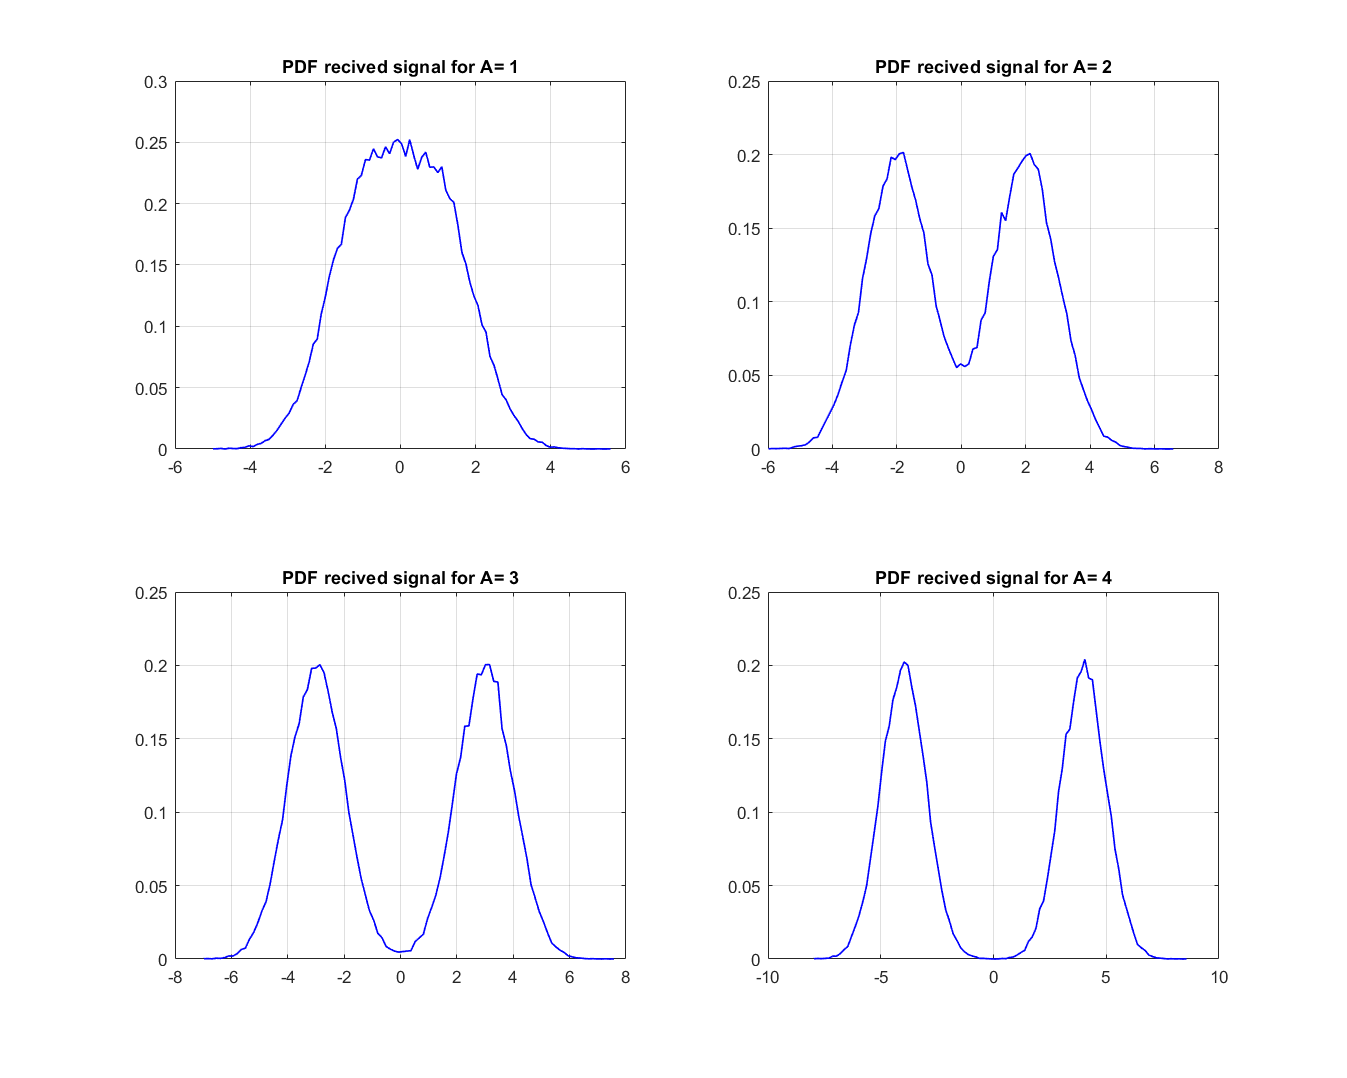

figure('Renderer','painters','Position',[10 10 1500 1200]);
for i=1:1:4
    
    subplot(2,2,i)
    plot(X_Values_total(i,:),Y_Values_total(i,:),'B-','linewidth',1);
    title(['PDF recived signal for A= ', num2str(i)])
    grid on
    
end

`We can see the symmetry approximately around 0. `


$$Question \; 6$$


`Now we need to consider the signal with extra noise (Interference) And check for the properties again as before. Now the received`

`signal can be taken as, `

## 
$$R= S + N + I$$
 

`Where I is an interference signal with mean=0 and variance of 1,`

`To compare the instances properly we will consider same data for S and N, and will generate a new value set for I.`

`First Let's check the impact on `$f_{R|S}(r|S=+A)$,

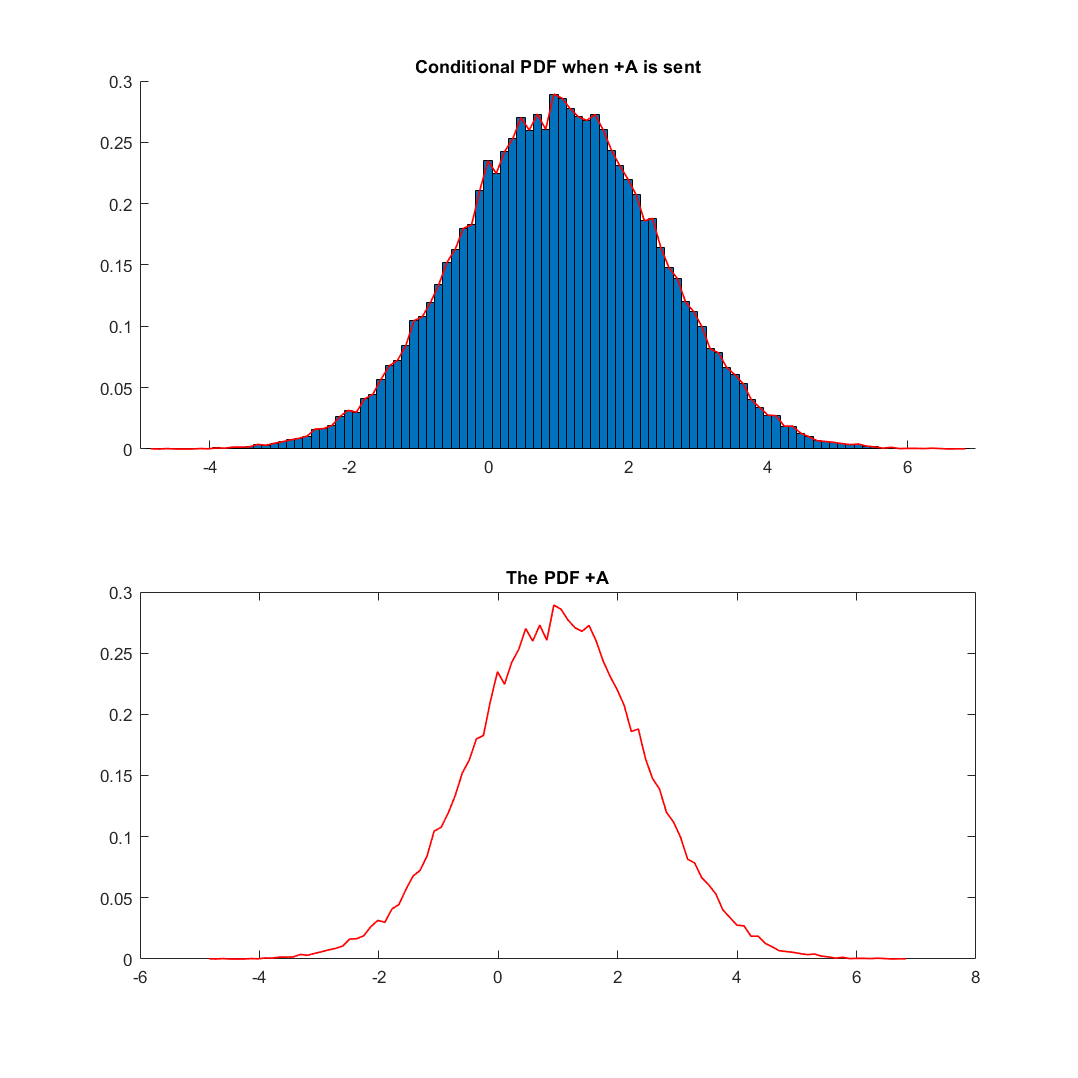

inter_f=randn(1,100000);

R_seq3_1=S_seq2+agwn_1_2+inter_f;

recived_end_Positive_1=[];
recived_end_Negative_1=[];
%since we need to compare A values,
A3=1;
for k1=1:length(S_seq2)
    if S_seq2(k1)==A3 % If the send value is +A
        recived_end_Positive_1(end+1)=R_seq3_1(k1);
    else %If the sent value is -A,
        recived_end_Negative_1(end+1)=R_seq3_1(k1); %When S=-A R(p) should be added to Rn
    end
end
 

% now we will plot the histograms   
  
Max_Positve_1=max(recived_end_Positive_1);
Min_Positive_1=min(recived_end_Positive_1);


% Make partitions in the given range to get "Bins" number of bins

x_values_3_positive_1=linspace(Min_Positive_1,Max_Positve_1,new_bin+1);


count_3_positive_1 =zeros(1,new_bin);

%now count each element and get the total count
for k1 = 1:length(recived_end_Positive_1)
    for k2=2:length(x_values_3_positive_1)  % take upper bound of each partition and compare;
        if recived_end_Positive_1(k1)<=x_values_3_positive_1(k2)
            count_3_positive_1(1,k2-1)=count_3_positive_1(1,k2 - 1)+1; %Increment the count by one and break
            break
        end
    end
end

%create the mid values for the bins
x_mids_3_Positive_1= (x_values_3_positive_1(1,2:new_bin+1) + x_values_3_positive_1(1,1:new_bin))/2;

%normalize the pdf
width_postive_1=(abs(Min_Positive_1)+abs(Max_Positve_1))/new_bin;
count_3_positive_1=count_3_positive_1/(length(recived_end_Positive_1)*width_postive_1);
%plot the bar diagram with calculated data
figure('Renderer','painters','Position',[10 10 1200 1200]);
subplot(2,1,1)
hold on
bar(x_mids_3_Positive_1,count_3_positive_1,1);
title('Conditional PDF when +A is sent'); %Now using built in function hist()
plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
hold off;
subplot(2,1,2)
plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
title("The PDF +A")

`We can see that after the interference, the data is more widely scattered. The pdf is widen up and the height is`

`reduced. The mean`

`is much changed. (Not noticeable)`

`Now let's check the impact on `$f_{R|S}(r|S=-A)$

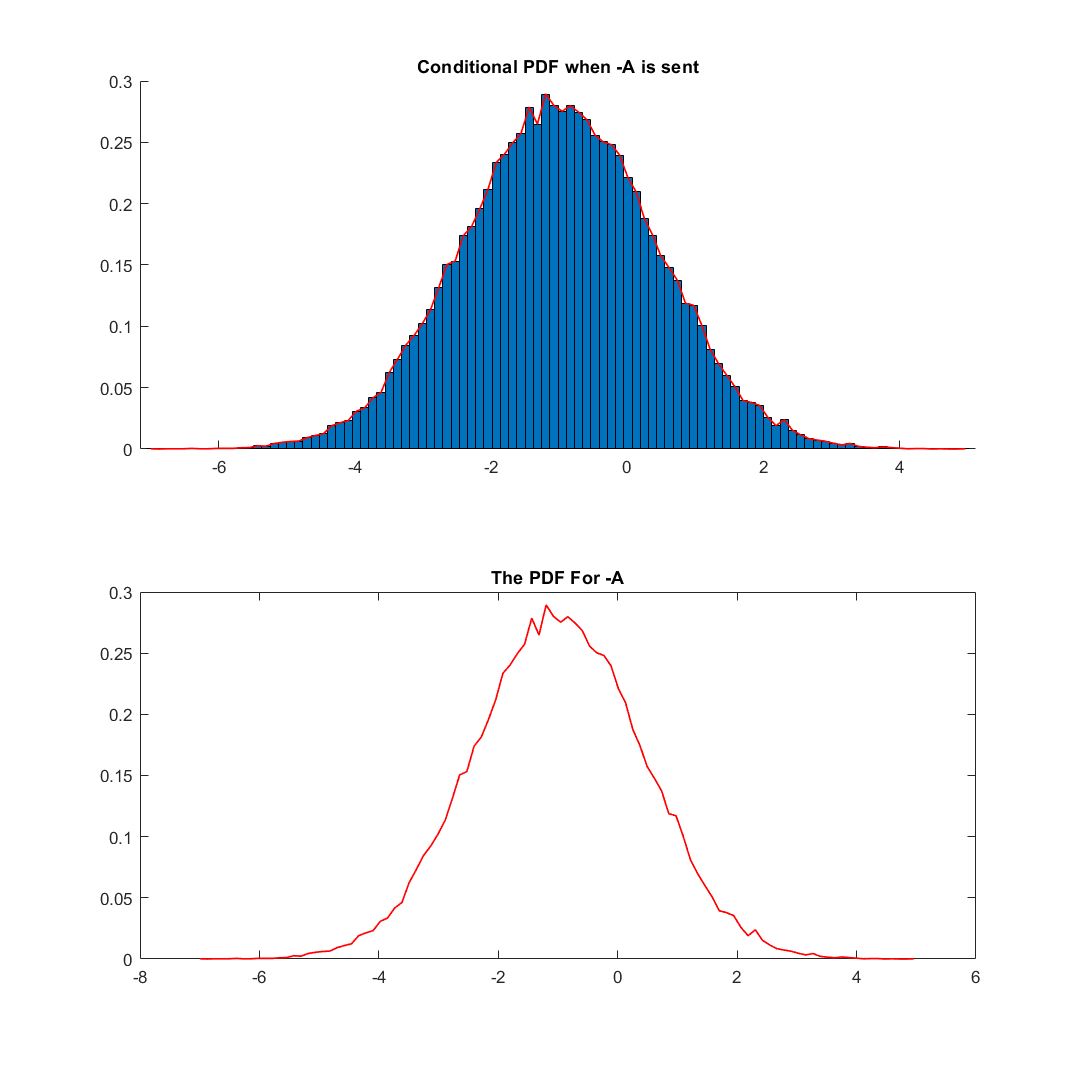

% now we will plot the histograms for -A
  
Max_Negative_1=max(recived_end_Negative_1);
Min_Negative_1=min(recived_end_Negative_1);


% Make partitions in the given range to get "Bins" number of bins

x_values_3_neagtive_1=linspace(Min_Negative_1,Max_Negative_1,new_bin+1);


count_3_negative_1 =zeros(1,new_bin);

%now count each element and get the total count
for k1 = 1:length(recived_end_Negative_1)
    for k2=2:length(x_values_3_neagtive_1)  % take upper bound of each partition and compare;
        if recived_end_Negative_1(k1)<=x_values_3_neagtive_1(k2)
            count_3_negative_1(1,k2-1)=count_3_negative_1(1,k2 - 1)+1; %Increment the count by one and break
            break
        end
    end
end

%create the mid values for the bins
x_mids_3_Negative_1= (x_values_3_neagtive_1(1,2:new_bin+1) + x_values_3_neagtive_1(1,1:new_bin))/2;

%normalize the pdf
width_postive_1=(abs(Min_Negative_1)+abs(Max_Negative_1))/new_bin;
count_3_negative_1=count_3_negative_1/(length(recived_end_Negative_1)*width_postive_1);
%plot the bar diagram with calculated data
figure('Renderer','painters','Position',[10 10 1200 1200]);
subplot(2,1,1)
hold on
bar(x_mids_3_Negative_1,count_3_negative_1,1);
title('Conditional PDF when -A is sent'); %Now using built in function hist()
plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
hold off;
subplot(2,1,2)
plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
title("The PDF For -A")

`We can see that after the interference, the data is more widely scattered. The pdf is widened up and the height is reduced. The mean`

`is much changed. (Not noticeable)`

`Same as before.`

`Now we will try to change the A and look at the signal behaviour with added interference.`

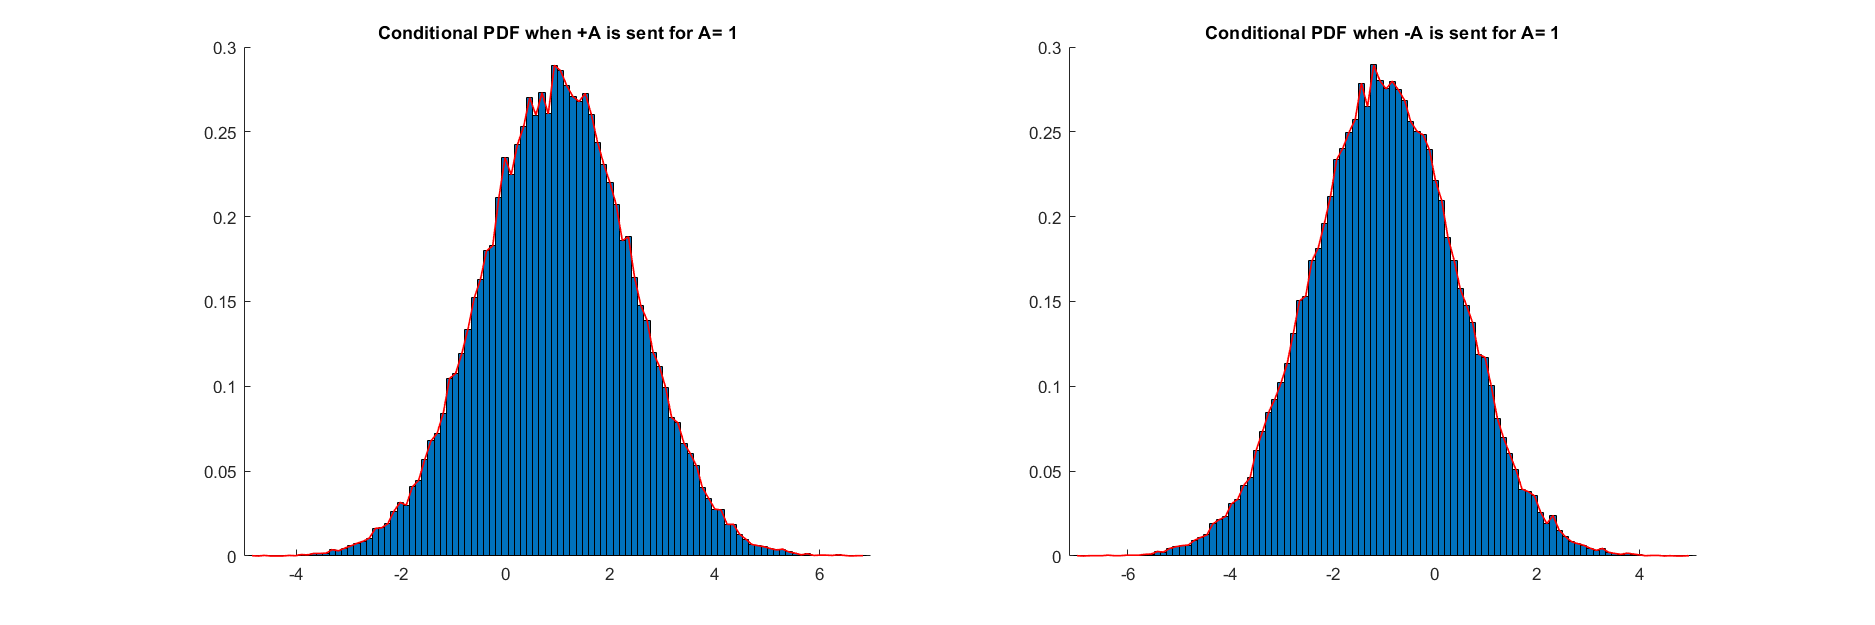

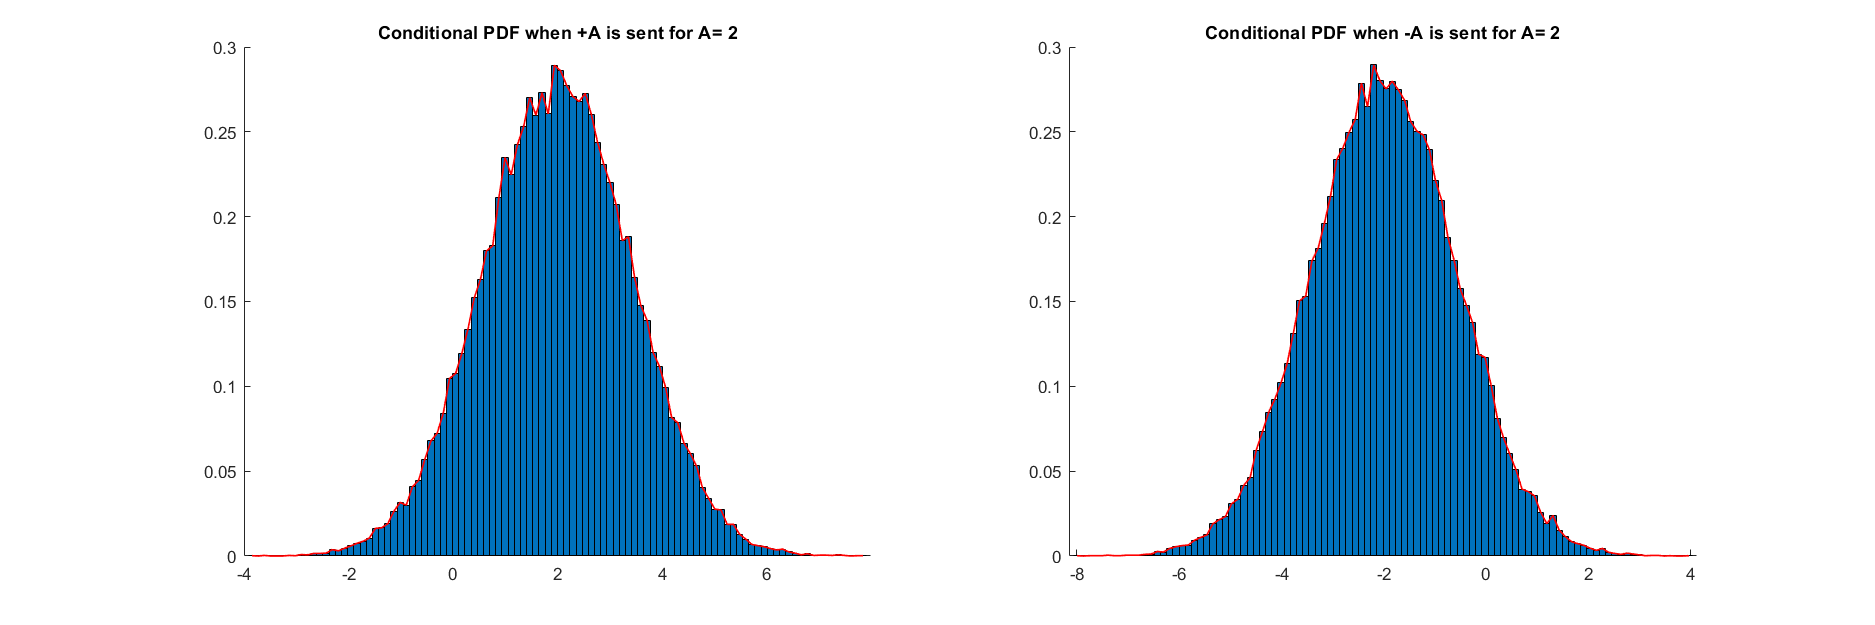

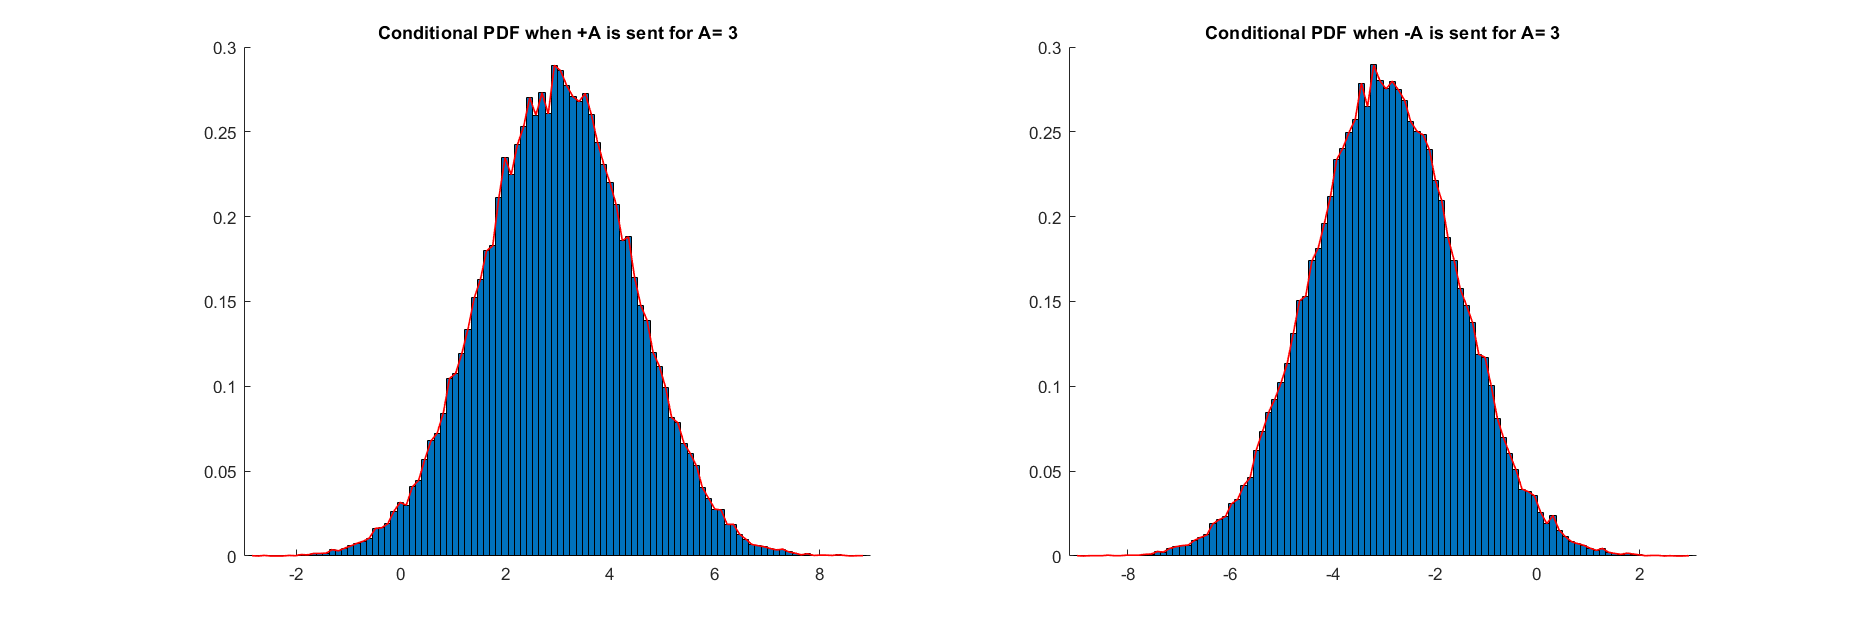

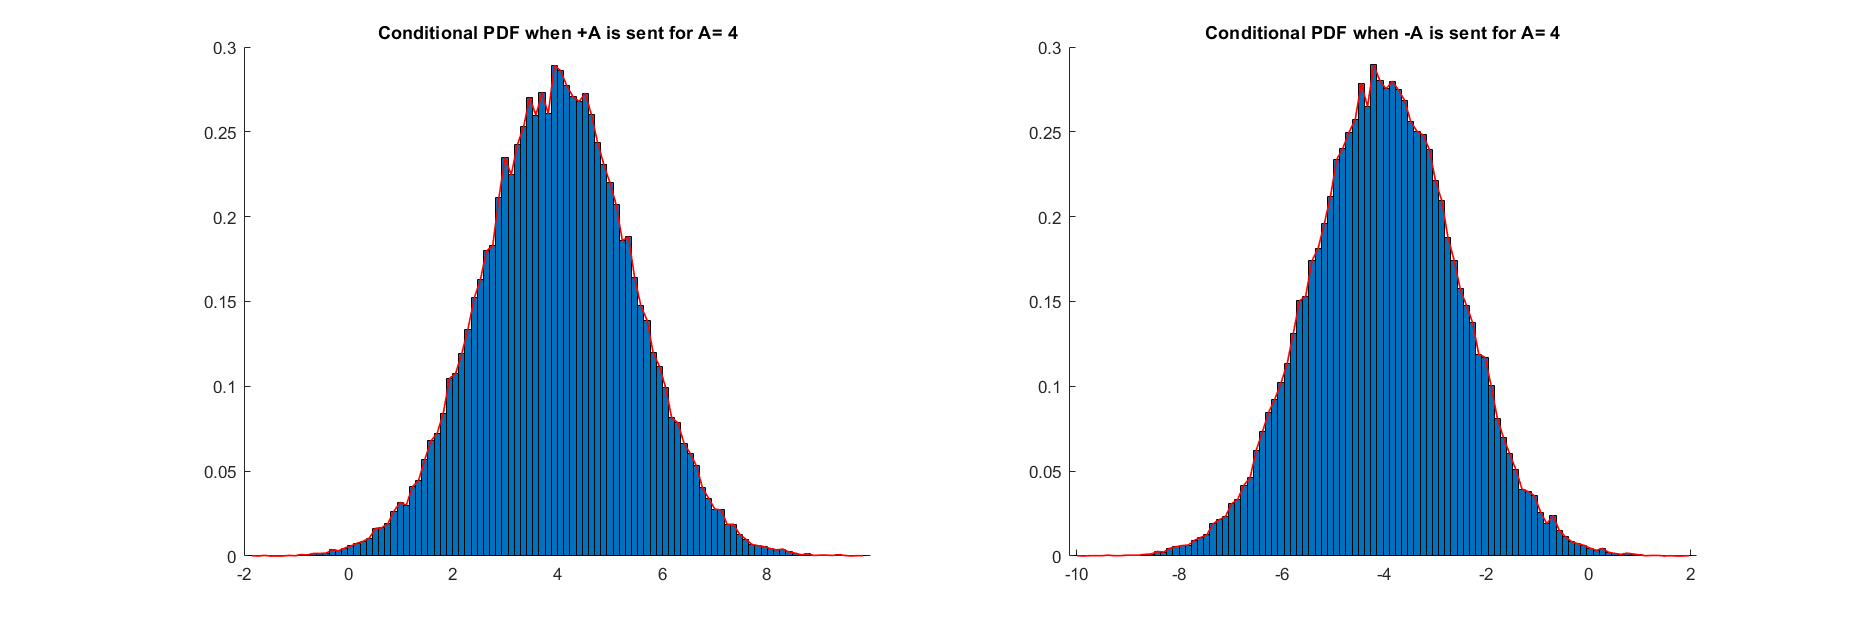

X_Values_array_positive=[];
X_Values_array_negative=[];
Y_Values_array_positive=[];
Y_Values_array_negative=[];
Rec_Values_array_total=[];
Width_values_array_negative=[];
Width_values_array_positive=[];
for AX=1:1:4
    
    
    S_seq3=[];
    for k1 = 1:length(binary_seq2)
        if binary_seq2(1,k1) == 0
            S_seq3(k1)=-AX;
        else
            S_seq3(k1)=AX;
        end
    end
    
    %Get the gaussian noise with varaince of 1
    
    
    
    %Recived sequance
    
    R_seq3_1=S_seq3+agwn_1_2+inter_f;
    
    Rec_Values_array_total(end+1, :)=R_seq3_1;

    %Decode with tau=0
    Y_seq_3=[];
    tao_2=0;
    for k1 = 1:length(binary_seq)
        if R_seq3_1(1,k1) <= tao_2
            Y_seq_3(k1)=-AX;
        else
            Y_seq_3(k1)=AX;
        end
    end
    
    
    recived_end_Positive_1=[];
    recived_end_Negative_1=[];
    %since we need to compare A values,
    
    for k1=1:length(S_seq3)
        if S_seq3(k1)==AX % If the send value is +A
            recived_end_Positive_1(end+1)=R_seq3_1(k1);
        else %If the sent value is -A,
            recived_end_Negative_1(end+1)=R_seq3_1(k1); %When S=-A R(p) should be added to Rn
        end
        
    end
    
    
    % now we will plot the histograms
    
    Max_Positve_1=max(recived_end_Positive_1);
    Min_Positive_1=min(recived_end_Positive_1);
    
    
    % Make partitions in the given range to get "Bins" number of bins
    
    x_values_3_positive_1=linspace(Min_Positive_1,Max_Positve_1,new_bin+1);
    
    
    count_3_positive_1 =zeros(1,new_bin);
    
    %now count each element and get the total count
    for k1 = 1:length(recived_end_Positive_1)
        for k2=2:length(x_values_3_positive_1)  % take upper bound of each partition and compare;
            if recived_end_Positive_1(k1)<=x_values_3_positive_1(k2)
                count_3_positive_1(1,k2-1)=count_3_positive_1(1,k2 - 1)+1; %Increment the count by one and break
                break
            end
        end
    end
    
    %create the mid values for the bins
    x_mids_3_Positive_1= (x_values_3_positive_1(1,2:new_bin+1) + x_values_3_positive_1(1,1:new_bin))/2;
    
    X_Values_array_positive( end+1, : )= x_mids_3_Positive_1;
    
    %normalize the pdf
    width_postive_1=(abs(Min_Positive_1)+abs(Max_Positve_1))/new_bin;
    Width_values_array_positive(end+1,1)=width_postive_1;
    
    count_3_positive_1=count_3_positive_1/(length(recived_end_Positive_1)*width_postive_1);
    Y_Values_array_positive( end+1, : )=count_3_positive_1;
    
    %plot the bar diagram with calculated data
    figure('Renderer','painters','Position',[10 10 1500 500]);
    subplot(1,2,1)
    hold on
    bar(x_mids_3_Positive_1,count_3_positive_1,1);
    title(['Conditional PDF when +A is sent for A= ', num2str(AX)]); %Now using built in function hist()
    plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
    hold off;
    %subplot(1,2,2)
    %plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
    %title("The PDF +A")
    
    % now we will plot the histograms for -A
    
    Max_Negative_1=max(recived_end_Negative_1);
    Min_Negative_1=min(recived_end_Negative_1);
    
    
    % Make partitions in the given range to get "new_bin" number of bins
    
    x_values_3_neagtive_1=linspace(Min_Negative_1,Max_Negative_1,new_bin+1);
    
    
    count_3_negative_1 =zeros(1,new_bin);
    
    %now count each element and get the total count
    for k1 = 1:length(recived_end_Negative_1)
        for k2=2:length(x_values_3_neagtive_1)  % take upper bound of each partition and compare;
            if recived_end_Negative_1(k1)<=x_values_3_neagtive_1(k2)
                count_3_negative_1(1,k2-1)=count_3_negative_1(1,k2 - 1)+1; %Increment the count by one and break
                break
            end
        end
    end
    
    %create the mid values for the bins
    x_mids_3_Negative_1= (x_values_3_neagtive_1(1,2:new_bin+1) + x_values_3_neagtive_1(1,1:new_bin))/2;
    
    X_Values_array_negative( end+1, : )=x_mids_3_Negative_1;
    
    %normalize the pdf
    width_negative_1=(abs(Min_Negative_1)+abs(Max_Negative_1))/new_bin;
    
    Width_values_array_negative(end+1,1)=width_negative_1;

    count_3_negative_1=count_3_negative_1/(length(recived_end_Negative_1)*width_negative_1);
    
    Y_Values_array_negative( end+1, : )=count_3_negative_1;
    
    %plot the bar diagram with calculated data
    %figure('Renderer','painters','Position',[10 10 1200 1200]);
    subplot(1,2,2)
    hold on
    bar(x_mids_3_Negative_1,count_3_negative_1,1);
    title(['Conditional PDF when -A is sent for A= ', num2str(AX)]); %Now using built in function hist()
    plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
    hold off;
    %subplot(2,1,2)
    %plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
    %title("The PDF For -A")
    
end

`Compared with the earlier scenario, the shift is still present. The PDF is flattened out. Since the variance in the `

`data is more this time due to the interference, the Domain is widened.`

`Using the same code we used earlier,`

% calculations for E(R);
X_Values_total=[];
Y_Values_total=[];
widths_total=[];
for Ax=1:1:4
    R_seq_6= Rec_Values_array_total(Ax,:);
    Max_x=max(R_seq_6);
    Min_x=min(R_seq_6);
    
    
    % Make partitions in the given range to get "new_bin" number of bins
    
    x_values_6=linspace(Min_x,Max_x,new_bin+1);
    
    
    count_6 =zeros(1,new_bin);
    
    %now count each element and get the total count
    for k1 = 1:length(R_seq_6)
        for k2=2:length(x_values_6)  % take upper bound of each partition and compare;
            if R_seq_6(k1)<=x_values_6(k2)
                count_6(1,k2-1)=count_6(1,k2 - 1)+1; %Increment the count by one and break
                break
            end
        end
    end
    
    width_6=(abs(Max_x)+abs(Min_x))/new_bin;
    %create the mid values for the bins
    widths_total(end+1,:)=width_6;
    
    x_mids_6= (x_values_6(1,2:new_bin+1) + x_values_6(1,1:new_bin))/2;
    X_Values_total(end+1,:)=x_mids_6;
    %normalized
    count_6=count_6/(length(R_seq_6)*width_6);
    Y_Values_total(end+1,:)=count_6;
    
end



%for positive 
E_vals_pos=X_Values_array_positive .* Y_Values_array_positive;
E_vals_pos=sum(E_vals_pos .*Width_values_array_positive,2);

E_vals_neg=X_Values_array_negative .* Y_Values_array_negative;
E_vals_neg=sum(E_vals_neg .*Width_values_array_negative,2);

E_vals_Total=X_Values_total.*Y_Values_total;
E_vals_Total=sum(E_vals_Total.*widths_total,2);

Eval_table=table;
A_Vals=[1;2;3;4];
Eval_table.('A Values')=A_Vals;
Eval_table.("+A Expected Value")=E_vals_pos;
Eval_table.("-A Expected Value")=E_vals_neg;
Eval_table.("Total Expected value Of received data")=E_vals_Total

Eval_table = 4×4 table
    A Values    +A Expected Value    -A Expected Value    Total Expected value Of received data
    ________    _________________    _________________    _____________________________________

       1             0.99451             -0.99753                       -0.0011707             
       2              1.9945              -1.9975                      -0.00074959             
       3              2.9945              -2.9975                       -0.0005528             
       4              3.9945              -3.9975                        0.0003498             


`The Expected Values have not changed much, compared to when the interference was absent. This is mostly due,`

`interference having zero mean.`

`To Plot the pdf of R signal with the interference, we will use the same code,`

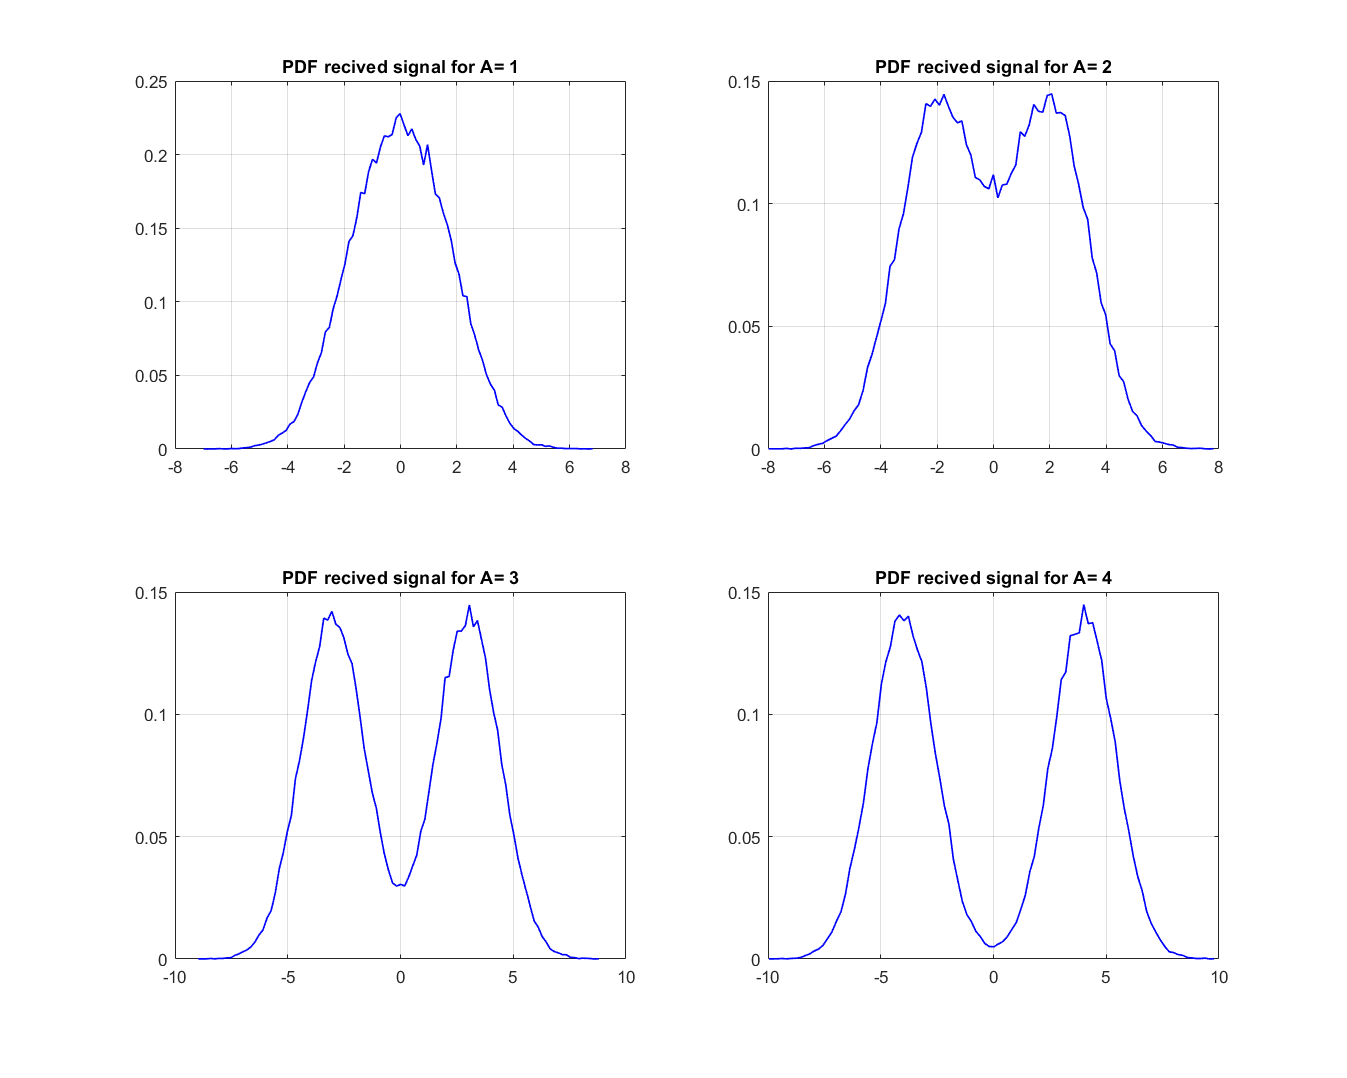

figure('Renderer','painters','Position',[10 10 1500 1200]);
for i=1:1:4
    
    subplot(2,2,i)
    
    plot(X_Values_total(i,:),Y_Values_total(i,:),'B-','linewidth',1);
    title(['PDF recived signal for A= ', num2str(i)])
    grid on
    
end

`The symmetry and the basic shapes are still the same, there is much more variation compared to earlier. The`

`probability for the mean value has changed noticeably.`


$$Question \; 7$$


`Now we have to introduce a new signal with a parameter ` `to the system and get a new signal. This time there is no interference.`

## 
$$R= \alpha S +N$$


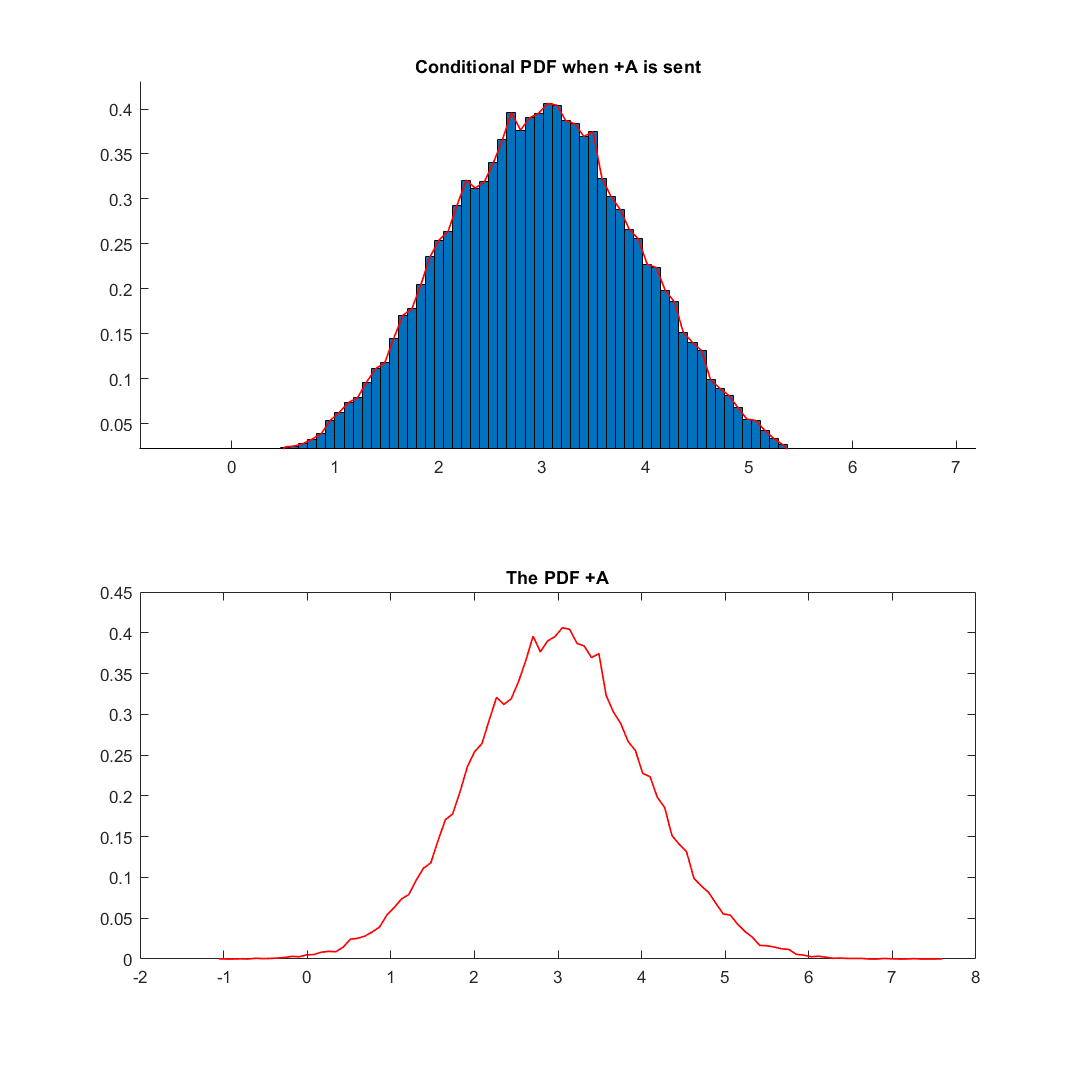

A_lpha=3;

R_seq4_1= (A_lpha * S_seq2) + agwn_1_2 ;

recived_end_Positive_1=[];
recived_end_Negative_1=[];
%since we need to compare A values,
A3=1;
for k1=1:length(S_seq2)
    if S_seq2(k1)==A3 % If the send value is +A
        recived_end_Positive_1(end+1)=R_seq4_1(k1);
    else %If the sent value is -A,
        recived_end_Negative_1(end+1)=R_seq4_1(k1); %When S=-A R(p) should be added to Rn
    end
end
 

% now we will plot the histograms   
  
Max_Positve_1=max(recived_end_Positive_1);
Min_Positive_1=min(recived_end_Positive_1);


% Make partitions in the given range to get "Bins" number of bins

x_values_3_positive_1=linspace(Min_Positive_1,Max_Positve_1,new_bin+1);


count_3_positive_1 =zeros(1,new_bin);

%now count each element and get the total count
for k1 = 1:length(recived_end_Positive_1)
    for k2=2:length(x_values_3_positive_1)  % take upper bound of each partition and compare;
        if recived_end_Positive_1(k1)<=x_values_3_positive_1(k2)
            count_3_positive_1(1,k2-1)=count_3_positive_1(1,k2 - 1)+1; %Increment the count by one and break
            break
        end
    end
end

%create the mid values for the bins
x_mids_3_Positive_1= (x_values_3_positive_1(1,2:new_bin+1) + x_values_3_positive_1(1,1:new_bin))/2;

%normalize the pdf
width_postive_1=(abs(Min_Positive_1)+abs(Max_Positve_1))/new_bin;
count_3_positive_1=count_3_positive_1/(length(recived_end_Positive_1)*width_postive_1);
%plot the bar diagram with calculated data
figure('Renderer','painters','Position',[10 10 1200 1200]);
subplot(2,1,1)
hold on
bar(x_mids_3_Positive_1,count_3_positive_1,1);
title('Conditional PDF when +A is sent'); %Now using built in function hist()
plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
hold off;
subplot(2,1,2)
plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
title("The PDF +A")

`When `$\alpha$ `is increased, the pdf will shift right. Since `$\alpha$ `is positive, on the positive half it has an increasing `

`property, and this will affect the +A PDF.`

`For the -A PDF part we will be using the same code.`

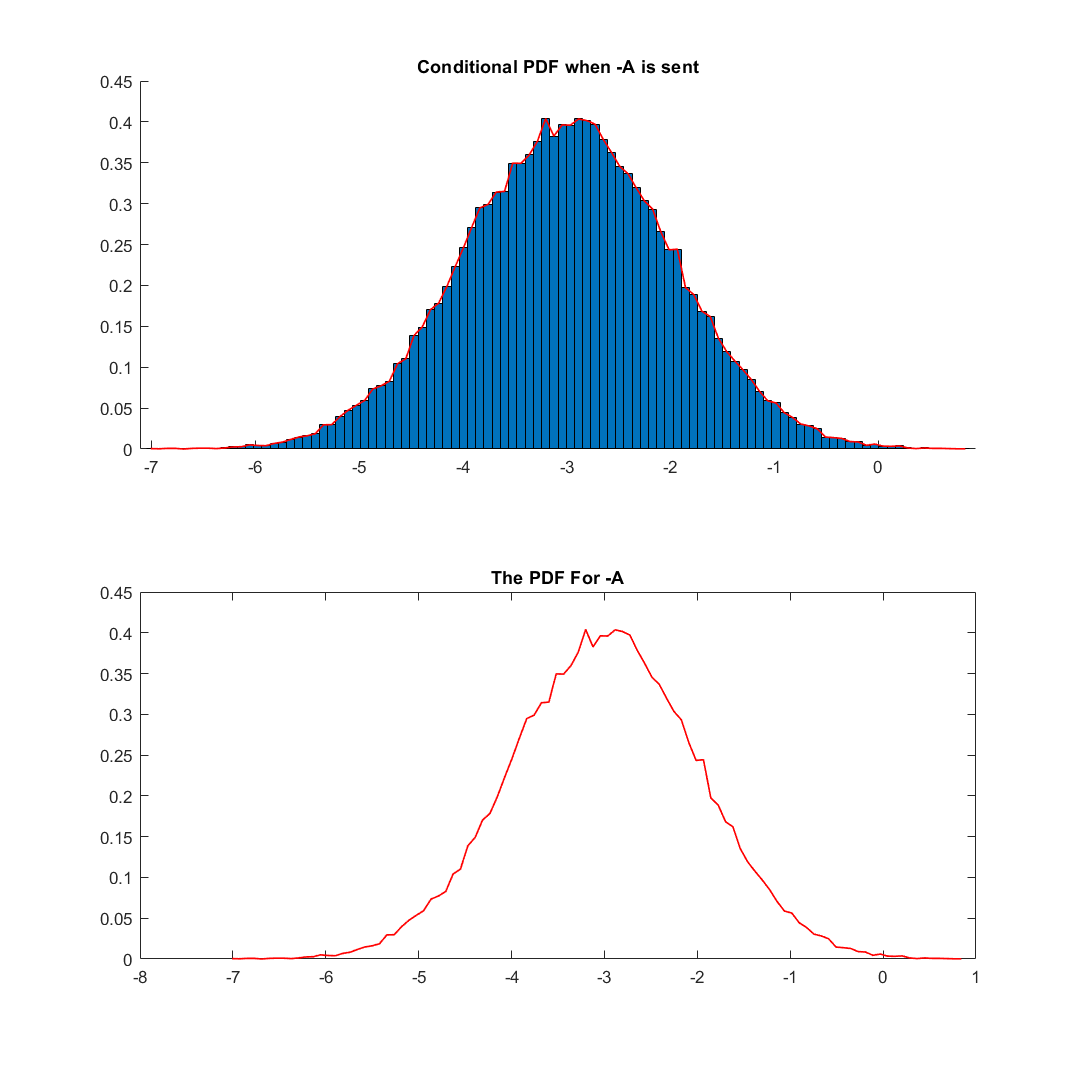

% now we will plot the histograms for -A
  
Max_Negative_1=max(recived_end_Negative_1);
Min_Negative_1=min(recived_end_Negative_1);


% Make partitions in the given range to get "Bins" number of bins

x_values_3_neagtive_1=linspace(Min_Negative_1,Max_Negative_1,new_bin+1);


count_3_negative_1 =zeros(1,new_bin);

%now count each element and get the total count
for k1 = 1:length(recived_end_Negative_1)
    for k2=2:length(x_values_3_neagtive_1)  % take upper bound of each partition and compare;
        if recived_end_Negative_1(k1)<=x_values_3_neagtive_1(k2)
            count_3_negative_1(1,k2-1)=count_3_negative_1(1,k2 - 1)+1; %Increment the count by one and break
            break
        end
    end
end

%create the mid values for the bins
x_mids_3_Negative_1= (x_values_3_neagtive_1(1,2:new_bin+1) + x_values_3_neagtive_1(1,1:new_bin))/2;

%normalize the pdf
width_postive_1=(abs(Min_Negative_1)+abs(Max_Negative_1))/new_bin;
count_3_negative_1=count_3_negative_1/(length(recived_end_Negative_1)*width_postive_1);
%plot the bar diagram with calculated data
figure('Renderer','painters','Position',[10 10 1200 1200]);
subplot(2,1,1)
hold on
bar(x_mids_3_Negative_1,count_3_negative_1,1);
title('Conditional PDF when -A is sent'); %Now using built in function hist()
plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
hold off;
subplot(2,1,2)
plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
title("The PDF For -A")

`On this section the positive property of the ` `will affect in amplitude increase and result in larger negative `

`results. Increase of ` `will introduce more shift.`

`Using the same algorithm as before, we will check the new changes occur when A is changed,`

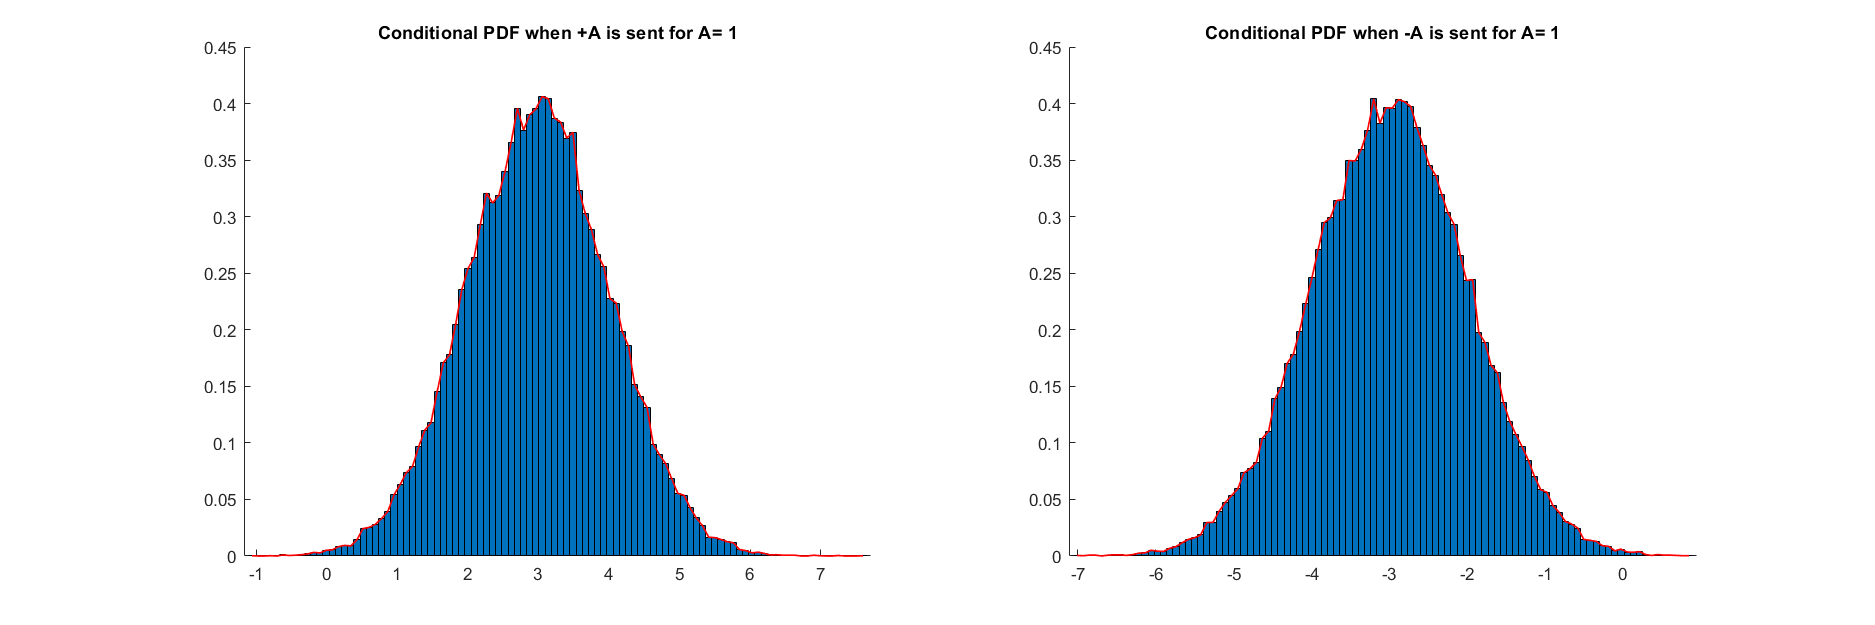

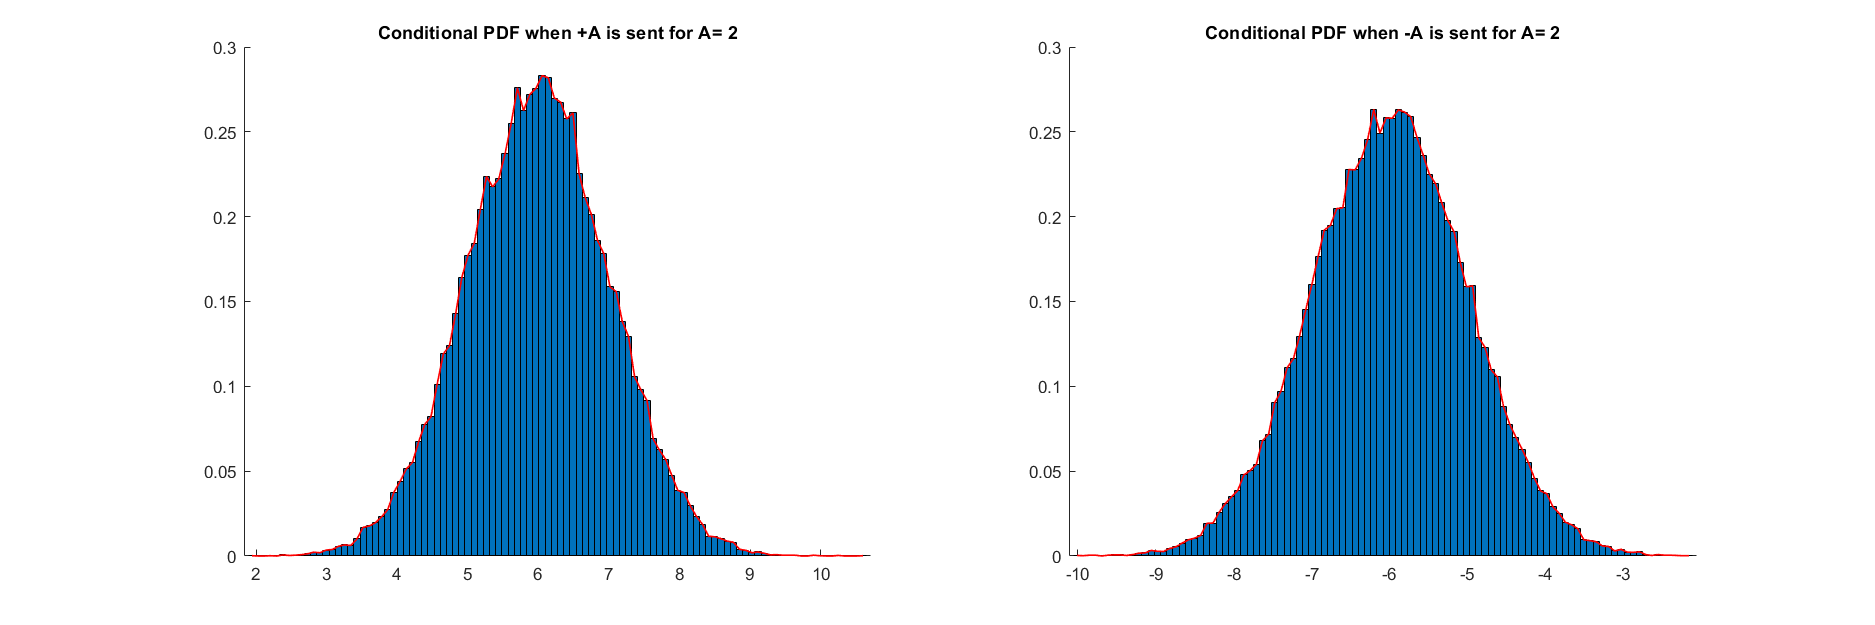

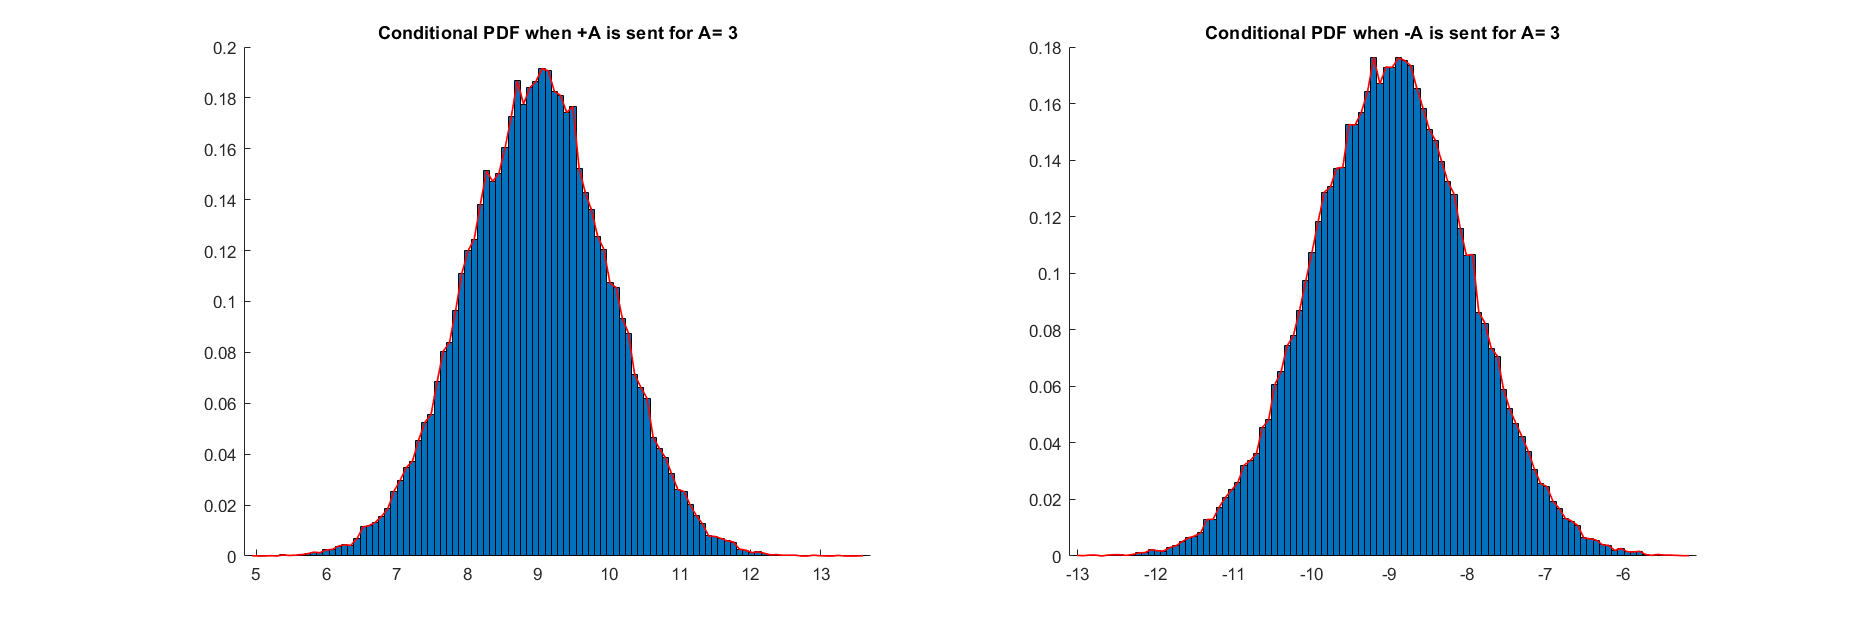

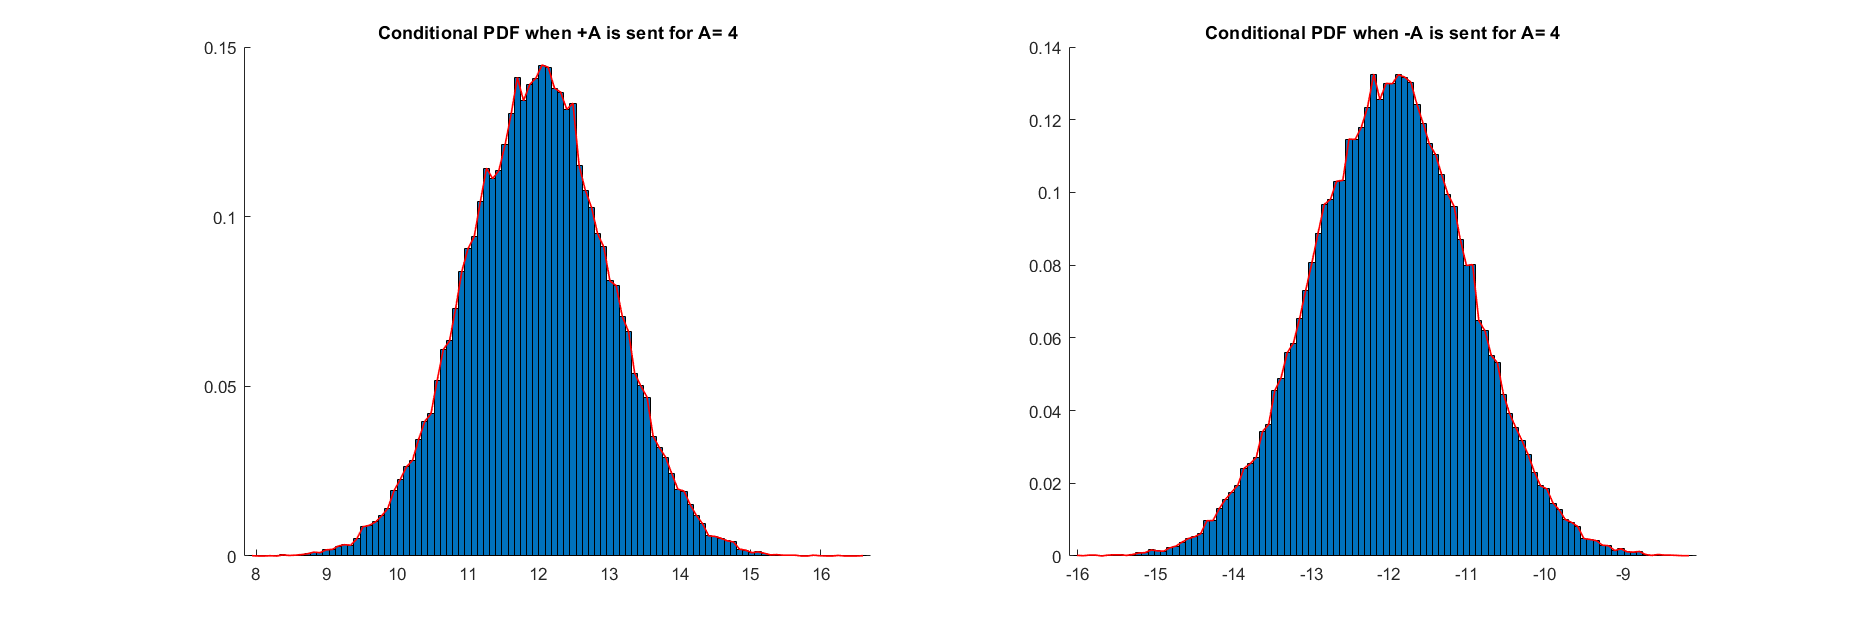

X_Values_array_positive=[];
X_Values_array_negative=[];
Y_Values_array_positive=[];
Y_Values_array_negative=[];
Rec_Values_array_total=[];
Width_values_array_negative=[];
Width_values_array_positive=[];
for AX=1:1:4
    
    
    S_seq3=[];
    for k1 = 1:length(binary_seq2)
        if binary_seq2(1,k1) == 0
            S_seq3(k1)=-AX;
        else
            S_seq3(k1)=AX;
        end
    end
    
    %Get the gaussian noise with varaince of 1
    
    
    
    %Recived sequance
    
    R_seq3_1=(A_lpha* S_seq3)+agwn_1_2;
    
    Rec_Values_array_total(end+1, :)=R_seq3_1;

    %Decode with tau=0
    Y_seq_3=[];
    tao_2=0;
    for k1 = 1:length(binary_seq)
        if R_seq3_1(1,k1) <= tao_2
            Y_seq_3(k1)=-AX;
        else
            Y_seq_3(k1)=AX;
        end
    end
    
    
    recived_end_Positive_1=[];
    recived_end_Negative_1=[];
    %since we need to compare A values,
    
    for k1=1:length(S_seq3)
        if S_seq3(k1)==AX % If the send value is +A
            recived_end_Positive_1(end+1)=R_seq3_1(k1);
        else %If the sent value is -A,
            recived_end_Negative_1(end+1)=R_seq3_1(k1); %When S=-A R(p) should be added to Rn
        end
        
    end
    
    
    % now we will plot the histograms
    
    Max_Positve_1=max(recived_end_Positive_1);
    Min_Positive_1=min(recived_end_Positive_1);
    
    
    % Make partitions in the given range to get "Bins" number of bins
    
    x_values_3_positive_1=linspace(Min_Positive_1,Max_Positve_1,new_bin+1);
    
    
    count_3_positive_1 =zeros(1,new_bin);
    
    %now count each element and get the total count
    for k1 = 1:length(recived_end_Positive_1)
        for k2=2:length(x_values_3_positive_1)  % take upper bound of each partition and compare;
            if recived_end_Positive_1(k1)<=x_values_3_positive_1(k2)
                count_3_positive_1(1,k2-1)=count_3_positive_1(1,k2 - 1)+1; %Increment the count by one and break
                break
            end
        end
    end
    
    %create the mid values for the bins
    x_mids_3_Positive_1= (x_values_3_positive_1(1,2:new_bin+1) + x_values_3_positive_1(1,1:new_bin))/2;
    
    X_Values_array_positive( end+1, : )= x_mids_3_Positive_1;
    
    %normalize the pdf
    width_postive_1=(abs(Min_Positive_1)+abs(Max_Positve_1))/new_bin;
    Width_values_array_positive(end+1,1)=width_postive_1;
    
    count_3_positive_1=count_3_positive_1/(length(recived_end_Positive_1)*width_postive_1);
    Y_Values_array_positive( end+1, : )=count_3_positive_1;
    
    %plot the bar diagram with calculated data
    figure('Renderer','painters','Position',[10 10 1500 500]);
    subplot(1,2,1)
    hold on
    bar(x_mids_3_Positive_1,count_3_positive_1,1);
    title(['Conditional PDF when +A is sent for A= ', num2str(AX)]); %Now using built in function hist()
    plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
    hold off;
    %subplot(1,2,2)
    %plot(x_mids_3_Positive_1,count_3_positive_1,'r-','linewidth',1);
    %title("The PDF +A")
    
    % now we will plot the histograms for -A
    
    Max_Negative_1=max(recived_end_Negative_1);
    Min_Negative_1=min(recived_end_Negative_1);
    
    
    % Make partitions in the given range to get "new_bin" number of bins
    
    x_values_3_neagtive_1=linspace(Min_Negative_1,Max_Negative_1,new_bin+1);
    
    
    count_3_negative_1 =zeros(1,new_bin);
    
    %now count each element and get the total count
    for k1 = 1:length(recived_end_Negative_1)
        for k2=2:length(x_values_3_neagtive_1)  % take upper bound of each partition and compare;
            if recived_end_Negative_1(k1)<=x_values_3_neagtive_1(k2)
                count_3_negative_1(1,k2-1)=count_3_negative_1(1,k2 - 1)+1; %Increment the count by one and break
                break
            end
        end
    end
    
    %create the mid values for the bins
    x_mids_3_Negative_1= (x_values_3_neagtive_1(1,2:new_bin+1) + x_values_3_neagtive_1(1,1:new_bin))/2;
    
    X_Values_array_negative( end+1, : )=x_mids_3_Negative_1;
    
    %normalize the pdf
    width_negative_1=(abs(Min_Negative_1)+abs(Max_Negative_1))/new_bin;
    
    Width_values_array_negative(end+1,1)=width_negative_1;

    count_3_negative_1=count_3_negative_1/(length(recived_end_Negative_1)*width_negative_1);
    
    Y_Values_array_negative( end+1, : )=count_3_negative_1;
    
    %plot the bar diagram with calculated data
    %figure('Renderer','painters','Position',[10 10 1200 1200]);
    subplot(1,2,2)
    hold on
    bar(x_mids_3_Negative_1,count_3_negative_1,1);
    title(['Conditional PDF when -A is sent for A= ', num2str(AX)]); %Now using built in function hist()
    plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
    hold off;
    %subplot(2,1,2)
    %plot(x_mids_3_Negative_1,count_3_negative_1,'r-','linewidth',1);
    %title("The PDF For -A")
    
end

`The hights are gradually decreasing, the shift is also can be seen as we observed earlier.`

`Now we will check the new expected values and how they have changed due to the alpha.`

% calculations for E(R);

X_Values_total=[];
Y_Values_total=[];
widths_total=[];

for Ax=1:1:4
    R_seq_6= Rec_Values_array_total(Ax,:);
    Max_x=max(R_seq_6);
    Min_x=min(R_seq_6);
    
    
    % Make partitions in the given range to get "new_bin" number of bins
    
    x_values_6=linspace(Min_x,Max_x,new_bin+1);
    
    
    count_6 =zeros(1,new_bin);
    
    %now count each element and get the total count
    for k1 = 1:length(R_seq_6)
        for k2=2:length(x_values_6)  % take upper bound of each partition and compare;
            if R_seq_6(k1)<=x_values_6(k2)
                count_6(1,k2-1)=count_6(1,k2 - 1)+1; %Increment the count by one and break
                break
            end
        end
    end
    
    width_6=(abs(Max_x)+abs(Min_x))/new_bin;
    %create the mid values for the bins
    widths_total(end+1,:)=width_6;
    
    x_mids_6= (x_values_6(1,2:new_bin+1) + x_values_6(1,1:new_bin))/2;
    X_Values_total(end+1,:)=x_mids_6;
    %normalized
    count_6=count_6/(length(R_seq_6)*width_6);
    Y_Values_total(end+1,:)=count_6;
    
end



%for positive 
E_vals_pos=X_Values_array_positive .* Y_Values_array_positive;
E_vals_pos=sum(E_vals_pos .*Width_values_array_positive,2);

E_vals_neg=X_Values_array_negative .* Y_Values_array_negative;
E_vals_neg=sum(E_vals_neg .*Width_values_array_negative,2);

E_vals_Total=X_Values_total.*Y_Values_total;
E_vals_Total=sum(E_vals_Total.*widths_total,2);

Eval_table=table;
A_Vals=[1;2;3;4];
Eval_table.('A Values')=A_Vals;
Eval_table.("+A Expected Value")=E_vals_pos;
Eval_table.("-A Expected Value")=E_vals_neg;
Eval_table.("Total Expected value Of received data")=E_vals_Total

Eval_table = 4×4 table
    A Values    +A Expected Value    -A Expected Value    Total Expected value Of received data
    ________    _________________    _________________    _____________________________________

       1             2.9928               -2.9929                       0.0013456              
       2             5.9928               -5.9929                       0.0023273              
       3             8.9928               -8.9929                         0.00426              
       4             11.993               -11.993                       0.0050097              


`Due to the shifting effect, the expected values have increased in magnitude for both +A and -A pdfs. But the`

`symmetry is still preserved so, the total expected values are still approximately 0. `

`Now we will plot the PDF of recived signal. This will also use the same algorithm.`

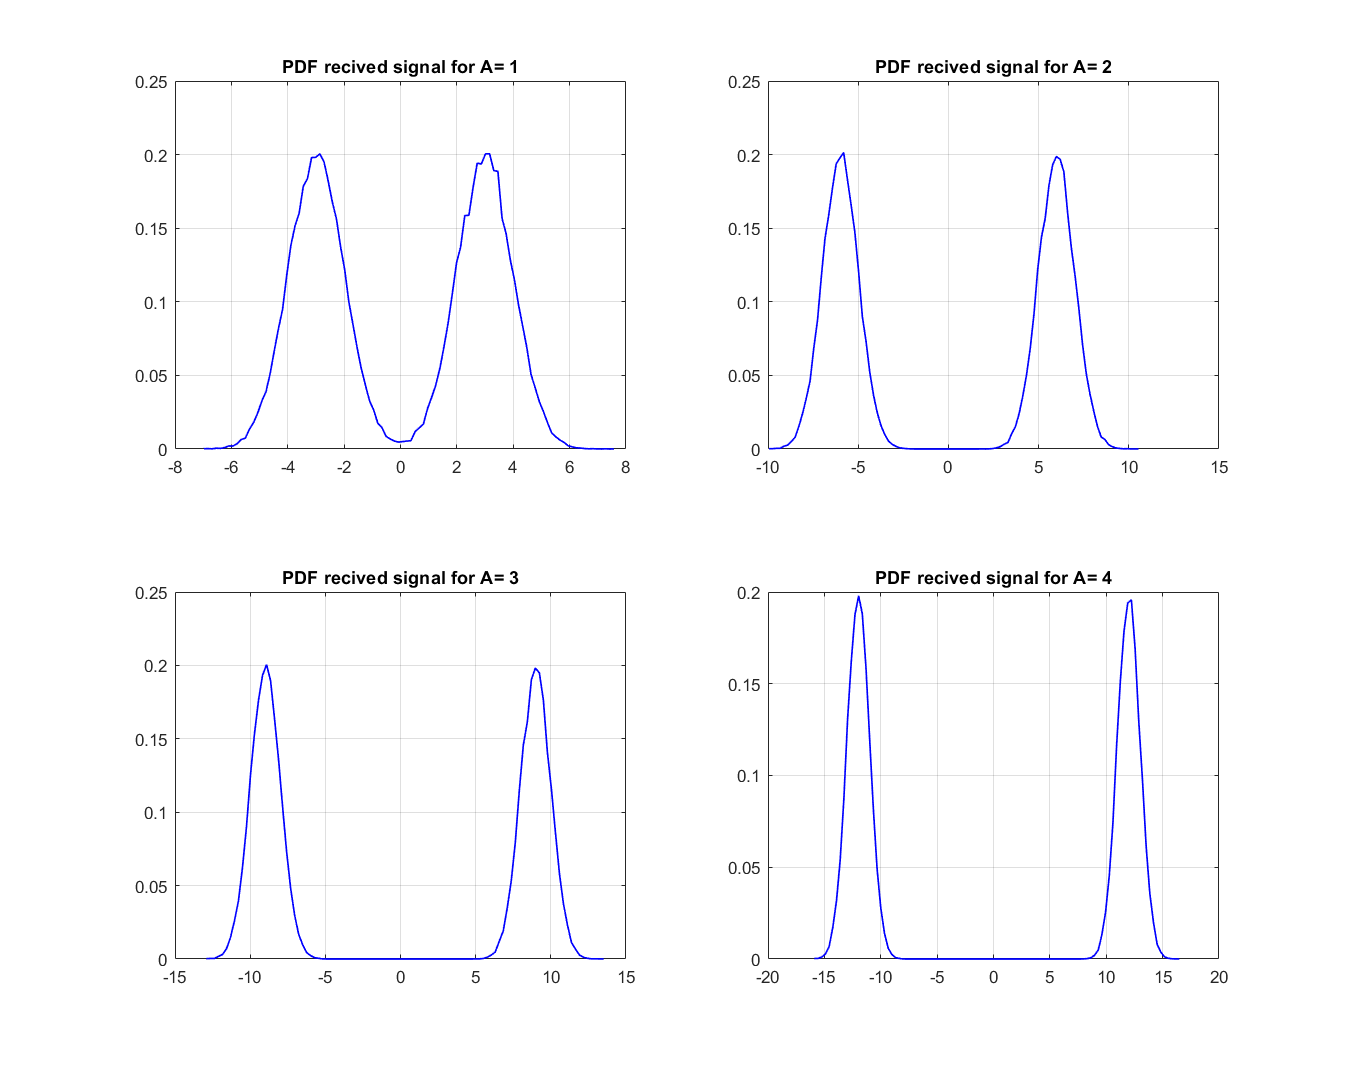

figure('Renderer','painters','Position',[10 10 1500 1200]);
for i=1:1:4
    
    subplot(2,2,i)
    
    plot(X_Values_total(i,:),Y_Values_total(i,:),'B-','linewidth',1);
    title(['PDF recived signal for A= ', num2str(i)])
    grid on
    
end

`The shifting property caused by `$\alpha$ `is greatly affected here. The separation is more visible since we observed`

`earlier those negative parts and positive parts shifted to different directions, causing larger separation.`

## `END`